Data and variables

% theta = Solid layer temperature
% T = liquid layer temperature
format long
rho_s = 917; % kg/m3 Density of ice
rho_l = 1000; % kg/m3 Density of water
k_s = 2.18; % W/mK Thermal conductivity of ice
k_l = 0.57; % W/mK Thermal conductivity of water
L_m = 3.34e5; % J/kg Latent heat of ice
T_m = 273; % K Melting temperature at melting interface => theta = T = T_m
mu_l = 0.001; % Ns/m2 Dynamic viscosity of water
alpha_l = 1.35e-7; %m2/s Thermal diffusivity of water
alpha_s = 1.16e-6; %m2/s Thermal diffusivity of ice
Cp_l = 4180; % kJ/kgK
Cp_s = 2100; % kJ/kgK
T_s = 287; % K Surface Temperature of substrate (surface on which melting happens)
theta_0 = 258; % K Initial temperature of ice

h_ss = 763; % W/m2 Heat transfer coefficient between solid ice & substrate
% Immediate melting only if h_ss -> infinity
% Applicable at beginning of pre melting stage before water appears on the surface

h_sl = 855; % W/m2 Heat transfer coefficient between water and substrate
% Applicable at end of pre melting stage when water appears on the surface
% In the limit h_sl -> infinity, standard condition of water temperature T(z=0) = T_s is possible

q = 0; % W/m2 heat flux from the substrate

H_0 = 0.05; % Initial height of block
L = 7/200; % Horizontal length of ice block is 2*L

Ste_eff = Cp_l*(T_s - T_m)/(L_m + Cp_s*(T_m - theta_0) );

Unsteady Analysis -

Stage 1 : Initial Pre-melting stage

% 𝛿(t) heat penetration depth from Heat balance Integral method

% 𝛿(t_1) Heat penetration depth at end of pre-melting stage

delta_1 = 3*k_s*(T_m - theta_0)/(q + h_ss*(T_s - T_m)) % Equation 26 is derived from Equation 23 by putting in it z = 0 & theta(0,t_1) = T_m

delta_1 =    0.009183673469388



t1 = (k_s^2/(12*alpha_s*h_ss^2))*((0.5*h_ss*delta_1/k_s)*(6 + h_ss*delta_1/k_s) - 9*log(1 + h_ss*delta_1/(3*k_s))); % Use equation 25 {which comes from the integration of 24} delta_1 Equation 26

delta_1_space = linspace(0,delta_1,100) % dividing 𝛿(t_1) = 𝛿_1 in 10 sub-lengths

delta_1_space =                    0   0.000092764378479   0.000185528756957   0.000278293135436   0.000371057513915   0.000463821892393   0.000556586270872   0.000649350649351   0.000742115027829   0.000834879406308   0.000927643784787   0.001020408163265   0.001113172541744   0.001205936920223   0.001298701298701   0.001391465677180   0.001484230055659   0.001576994434137   0.001669758812616   0.001762523191095   0.001855287569573   0.001948051948052   0.002040816326531   0.002133580705009   0.002226345083488   0.002319109461967   0.002411873840445   0.002504638218924   0.002597402597403   0.002690166975881   0.002782931354360   0.002875695732839   0.002968460111317   0.003061224489796   0.003153988868275   0.003246753246753   0.003339517625232   0.003432282003711   0.003525046382189   0.003617810760668   0.003710575139147   0.003803339517625   0.003896103896104   0.003988868274583   0.004081632653061   0.004174397031540   0.004267161410019   0.004359925788497   0.004452690166976   0

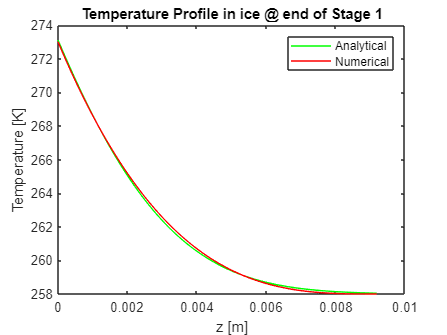


theta_t1 = theta_0 + ((q + h_ss*(T_s - theta_0)).*(delta_1 - delta_1_space).^3)./((delta_1^2).*(3*k_s + h_ss*delta_1)); % Equation 23

% General Expression - Ice temperature at z,t in Stage 1
temp_ice_z_t =@(z,t) theta_0 + ((q - h_ss*(theta_0 - T_s))/h_ss)*(erfc(z./(2*(alpha_s.*t).^0.5)) - ...
    exp(h_ss.*z/k_s + alpha_s.*t*(h_ss/k_s)^2)*erfc(z./(2*(alpha_s.*t).^0.5)+h_ss*(alpha_s.*t)^0.5/k_s)); % Equation 21 

% beyond 𝛿(t) the temperature rise above initial value is negligible

for i=1:length(delta_1_space)
    theta_z_t_1(i) = temp_ice_z_t(delta_1_space(i),t1); % temperature profile in ice @ end of Stage 1
end


figure(1)
plot(delta_1_space,theta_z_t_1,'g')
hold on
plot(delta_1_space,theta_t1,'r')
hold off
legend("Analytical","Numerical")
ylabel("Temperature [K]")
xlabel("z [m]")
title("Temperature Profile in ice @ end of Stage 1")

 Stage 2 : Initial Melting stage

% Theta(0) reaches T_m in time t_1 as seen in Stage 1

% h_m(t) thickness of melted solid
% H(t) = H_0 - h_m(t) time varying height of the block

% h = h(t) = height of melt layer not equals to h_m as liquid squeezes out at the edges

% at z = H(t) + h(t) the surface is insulated so dtheta/dz = 0

T_z_t_f = @(h,z) T_m - (q + h_sl*(T_s - T_m))*(z - h)/(k_l + h_sl*h) % Temperature in water layer

T_z_t_f = function_handle with value:
    @(h,z)T_m-(q+h_sl*(T_s-T_m))*(z-h)/(k_l+h_sl*h)



theta_t2_f = @(h,delta,z) theta_0 + (T_m -theta_0)*((delta - z)/(delta -h)).^3 % temperature in ice in stage 2

theta_t2_f = function_handle with value:
    @(h,delta,z)theta_0+(T_m-theta_0)*((delta-z)/(delta-h)).^3


t_step = 0.5;
tRange = 0:t_step:165;
y0 =[1e-8;1e-8;delta_1];
opts = odeset('RelTol',1e-4);
%ode solver for differential equations, function at the end of live script
[tsol,Ysol] = ode23s(@(t,Y) im_ODEfun(t,Y,k_s,theta_0,L_m,h_sl,rho_s,rho_l,T_m,T_s,q,k_l,mu_l,H_0,L,alpha_s),tRange,y0,opts);

h_m_im =      1.000000000000000e-08


h_im =      1.000000000000000e-08


delta_im =    0.009183673469388


dYdt =    0.000004204705598
   0.000003855715033
   0.001504167838700


h_m_im =      1.000001490116119e-08


h_im =      1.000000000000000e-08


delta_im =    0.009183673469388


dYdt =    0.000004204705598
   0.000003855715033
   0.001504167838700


h_m_im =      1.000000000000000e-08


h_im =      1.000001490116119e-08


delta_im =    0.009183673469388


dYdt =    0.000004204705597
   0.000003855715032
   0.001504167838705


h_m_im =      1.000000000000000e-08


h_im =      1.000000000000000e-08


delta_im =    0.009183673606235


dYdt =    0.000004204706118
   0.000003855715510
   0.001504167814684


h_m_im =      1.012207031250000e-08


h_im =      1.000000000000000e-08


delta_im =    0.009183673469388


dYdt =    0.000004204705598
   0.000003855715033
   0.001504167838700


h_m_im =      1.000000000000000e-08


h_im =      1.000000000000000e-08


delta_im =    0.009183673469388


dYdt =    0.000004204705598
   0.000003855715033
   0.001504167838700


h_m_im =      1.000000000000000e-08


h_im =      1.000000000000000e-08


delta_im =    0.009183673469388


dYdt =    0.000004204705598
   0.000003855715033
   0.001504167838700


h_m_im =      7.734380391008322e-07


h_im =      7.100726806136673e-07


delta_im =    0.009423388575692


dYdt =    0.000005048393199
   0.000004629343700
   0.001463398920329


h_m_im =      1.643300877473663e-06


h_im =      1.507726256274364e-06


delta_im =    0.009657923398296


dYdt =    0.000005824580474
   0.000005340825690
   0.001425506188717


h_m_im =      1.645306859990110e-06


h_im =      1.507726256274364e-06


delta_im =    0.009657923398296


dYdt =    0.000005824580474
   0.000005340825690
   0.001425506188717


h_m_im =      1.643300877473663e-06


h_im =      1.507726278741236e-06


delta_im =    0.009657923398296


dYdt =    0.000005824580473
   0.000005340825689
   0.001425506188724


h_m_im =      1.643300877473663e-06


h_im =      1.507726256274364e-06


delta_im =    0.009657923542210


dYdt =    0.000005824580969
   0.000005340826143
   0.001425506165873


h_m_im =      1.643300877473663e-06


h_im =      1.507726256274364e-06


delta_im =    0.009657923398296


dYdt =    0.000005824580474
   0.000005340825690
   0.001425506188717


h_m_im =      4.123111034426057e-06


h_im =      3.781290934306944e-06


delta_im =    0.010163747845432


dYdt =    0.000007336296563
   0.000006722421492
   0.001349915985833


h_m_im =      7.005645379457854e-06


h_im =      6.421306099451808e-06


delta_im =    0.010649032964457


dYdt =    0.000008613557262
   0.000007874331156
   0.001284326638339


h_m_im =      7.091163511531314e-06


h_im =      6.421306099451808e-06


delta_im =    0.010649032964457


dYdt =    0.000008613557262
   0.000007874331197
   0.001284326638214


h_m_im =      7.005645379457854e-06


h_im =      6.421306195136726e-06


delta_im =    0.010649032964457


dYdt =    0.000008613557256
   0.000007874331149
   0.001284326638369


h_m_im =      7.005645379457854e-06


h_im =      6.421306099451808e-06


delta_im =    0.010649033123140


dYdt =    0.000008613557711
   0.000007874331567
   0.001284326617602


h_m_im =      7.005645379457854e-06


h_im =      6.421306099451808e-06


delta_im =    0.010649032964457


dYdt =    0.000008613557262
   0.000007874331156
   0.001284326638339


h_m_im =      1.114099481832951e-05


h_im =      1.019167098909730e-05


delta_im =    0.011196651965409


dYdt =    0.000009861086436
   0.000008945464278
   0.001217525061427


h_m_im =      1.567276091071152e-05


h_im =      1.428251745025673e-05


delta_im =    0.011722481959837


dYdt =    0.000010905754357
   0.000009733220457
   0.001159710731598


h_m_im =      1.586407879292235e-05


h_im =      1.428251745025673e-05


delta_im =    0.011722481959837


dYdt =    0.000010905754357
   0.000009733221480
   0.001159710728528


h_m_im =      1.567276091071152e-05


h_im =      1.428251766308282e-05


delta_im =    0.011722481959837


dYdt =    0.000010905754345
   0.000009733220433
   0.001159710731690


h_m_im =      1.567276091071152e-05


h_im =      1.428251745025673e-05


delta_im =    0.011722482134516


dYdt =    0.000010905754765
   0.000009733220831
   0.001159710712737


h_m_im =      1.567276091071152e-05


h_im =      1.428251745025673e-05


delta_im =    0.011722481959837


dYdt =    0.000010905754357
   0.000009733220457
   0.001159710731598


h_m_im =      2.166483210982026e-05


h_im =      1.954819447518672e-05


delta_im =    0.012306904195870


dYdt =    0.000011901585798
   0.000010228354333
   0.001102186809389


h_m_im =      2.803112415165244e-05


h_im =      2.490095063742434e-05


delta_im =    0.012869301143854


dYdt =    0.000012738206017
   0.000010264435155
   0.001052947452422


h_m_im =      2.837330096014429e-05


h_im =      2.490095063742434e-05


delta_im =    0.012869301143854


dYdt =    0.000012738206017
   0.000010264444854
   0.001052947423324


h_m_im =      2.803112415165244e-05


h_im =      2.490095100847742e-05


delta_im =    0.012869301143854


dYdt =    0.000012738205996
   0.000010264435073
   0.001052947452701


h_m_im =      2.803112415165244e-05


h_im =      2.490095063742434e-05


delta_im =    0.012869301335622


dYdt =    0.000012738206389
   0.000010264435496
   0.001052947435217


h_m_im =      2.803112415165244e-05


h_im =      2.490095063742434e-05


delta_im =    0.012869301143854


dYdt =    0.000012738206017
   0.000010264435155
   0.001052947452422


h_m_im =      3.554777514240931e-05


h_im =      3.066026432926689e-05


delta_im =    0.013452402074072


dYdt =    0.000013499707034
   0.000009735416257
   0.001007916964990


h_m_im =      4.338868664217868e-05


h_im =      3.599924992600283e-05


delta_im =    0.014016704448150


dYdt = 1.0e-03 *

   0.014169920580466
   0.008715080194982
   0.969512689586444


h_m_im =      4.391833369591621e-05


h_im =      3.599924992600283e-05


delta_im =    0.014016704448150


dYdt = 1.0e-03 *

   0.014169920580466
   0.008715125558756
   0.969512553495122


h_m_im =      4.338868664217868e-05


h_im =      3.599925046243346e-05


delta_im =    0.014016704448150


dYdt = 1.0e-03 *

   0.014169920551280
   0.008715079976943
   0.969512690278763


h_m_im =      4.338868664217868e-05


h_im =      3.599924992600283e-05


delta_im =    0.014016704657015


dYdt = 1.0e-03 *

   0.014169920922730
   0.008715080508838
   0.969512673770214


h_m_im =      4.338868664217868e-05


h_im =      3.599924992600283e-05


delta_im =    0.014016704448150


dYdt = 1.0e-03 *

   0.014169920580466
   0.008715080194982
   0.969512689586444


h_m_im =      5.196758270472232e-05


h_im =      4.075844925298336e-05


delta_im =    0.014575661109414


dYdt = 1.0e-03 *

   0.014793993319988
   0.007357207049451
   0.935623130957089


h_m_im =      6.083408520427150e-05


h_im =      4.476950343726914e-05


delta_im =    0.015119712381796


dYdt = 1.0e-03 *

   0.015375770772846
   0.005872792400017
   0.905768206239912


h_m_im =      6.157668878342520e-05


h_im =      4.476950343726914e-05


delta_im =    0.015119712381796


dYdt = 1.0e-03 *

   0.015375770772846
   0.005872914733724
   0.905767839238794


h_m_im =      6.083408520427150e-05


h_im =      4.476950410438673e-05


delta_im =    0.015119712381796


dYdt = 1.0e-03 *

   0.015375770737565
   0.005872791999898
   0.905768207481134


h_m_im =      6.083408520427150e-05


h_im =      4.476950343726914e-05


delta_im =    0.015119712607097


dYdt = 1.0e-03 *

   0.015375771090391
   0.005872792691206
   0.905768191565951


h_m_im =      6.083408520427150e-05


h_im =      4.476950343726914e-05


delta_im =    0.015119712381796


dYdt = 1.0e-03 *

   0.015375770772846
   0.005872792400017
   0.905768206239912


h_m_im =      7.066646483918089e-05


h_im =      4.799455940703408e-05


delta_im =    0.015674699060379


dYdt = 1.0e-03 *

   0.015960710874045
   0.004502131485328
   0.877276431771683


h_m_im =      8.078822591268187e-05


h_im =      5.053927974043459e-05


delta_im =    0.016216013019712


dYdt = 1.0e-03 *

   0.016514480895972
   0.003313441683647
   0.851154142324951


h_m_im =      8.177441031103003e-05


h_im =      5.053927974043459e-05


delta_im =    0.016216013019712


dYdt = 1.0e-03 *

   0.016514480895972
   0.003313675399158
   0.851153441178419


h_m_im =      8.078822591268187e-05


h_im =      5.053928049352854e-05


delta_im =    0.016216013019712


dYdt = 1.0e-03 *

   0.016514480856903
   0.003313441118964
   0.851154144059117


h_m_im =      8.078822591268187e-05


h_im =      5.053927974043459e-05


delta_im =    0.016216013261350


dYdt = 1.0e-03 *

   0.016514481192142
   0.003313441955235
   0.851154128638765


h_m_im =      8.078822591268187e-05


h_im =      5.053927974043459e-05


delta_im =    0.016216013019712


dYdt = 1.0e-03 *

   0.016514480895972
   0.003313441683647
   0.851154142324951


h_m_im =      9.272674231878211e-05


h_im =      5.253807955695193e-05


delta_im =    0.016806143533336


dYdt = 3×1
1.0e-03 *

   0.017109072796476
   0.002401966158790
   0.823660032943764


h_m_im =      1.049952333057166e-04


h_im =      5.407417861362352e-05


delta_im =    0.017381182516311


dYdt = 3×1
1.0e-03 *

   0.017664645070517
   0.001715126216795
   0.798220060562295


h_m_im =      1.062769133997805e-04


h_im =      5.407417861362352e-05


delta_im =    0.017381182516311


dYdt = 3×1
1.0e-03 *

   0.017664645070517
   0.001715498258560
   0.798218944437000


h_m_im =      1.049952333057166e-04


h_im =      5.407417941939157e-05


delta_im =    0.017381182516311


dYdt = 3×1
1.0e-03 *

   0.017664645029243
   0.001715125531490
   0.798220062655568


h_m_im =      1.049952333057166e-04


h_im =      5.407417861362352e-05


delta_im =    0.017381182775311


dYdt = 3×1
1.0e-03 *

   0.017664645346830
   0.001715126470174
   0.798220047793722


h_m_im =      1.049952333057166e-04


h_im =      5.407417861362352e-05


delta_im =    0.017381182516311


dYdt = 3×1
1.0e-03 *

   0.017664645070517
   0.001715126216795
   0.798220060562295


h_m_im =      1.205023575258596e-04


h_im =      5.533912050158585e-05


delta_im =    0.018052100475791


dYdt = 3×1
1.0e-03 *

   0.018289143266982
   0.001252238757228
   0.769715783873938


h_m_im =      1.364242507761817e-04


h_im =      5.633308498072668e-05


delta_im =    0.018704148424070


dYdt = 3×1
1.0e-03 *

   0.018860898711488
   0.000930433645035
   0.743676837389989


h_m_im =      1.380895858686644e-04


h_im =      5.633308498072668e-05


delta_im =    0.018704148424070


dYdt = 3×1
1.0e-03 *

   0.018860898711488
   0.000930980200829
   0.743675197722607


h_m_im =      1.364242507761817e-04


h_im =      5.633308582015506e-05


delta_im =    0.018704148424070


dYdt = 3×1
1.0e-03 *

   0.018860898668874
   0.000930432874385
   0.743676839735540


h_m_im =      1.364242507761817e-04


h_im =      5.633308498072668e-05


delta_im =    0.018704148702783


dYdt = 3×1
1.0e-03 *

   0.018860898968205
   0.000930433880445
   0.743676825526915


h_m_im =      1.364242507761817e-04


h_im =      5.633308498072668e-05


delta_im =    0.018704148424070


dYdt = 3×1
1.0e-03 *

   0.018860898711488
   0.000930433645035
   0.743676837389989


h_m_im =      1.574012424075447e-04


h_im =      5.724341941234525e-05


delta_im =    0.019494269946308


dYdt = 3×1
1.0e-03 *

   0.019512992051955
   0.000729368656717
   0.713970817862071


h_m_im =      1.789195469074675e-04


h_im =      5.799921631361662e-05


delta_im =    0.020259769556849


dYdt = 3×1
1.0e-03 *

   0.020099260706351
   0.000585807222876
   0.687291100582367


h_m_im =      1.811036234078028e-04


h_im =      5.799921631361662e-05


delta_im =    0.020259769556849


dYdt = 3×1
1.0e-03 *

   0.020099260706351
   0.000586589528560
   0.687288753665317


h_m_im =      1.789195469074675e-04


h_im =      5.799921717787229e-05


delta_im =    0.020259769556849


dYdt = 3×1
1.0e-03 *

   0.020099260662793
   0.000585806385190
   0.687291103124903


h_m_im =      1.789195469074675e-04


h_im =      5.799921631361662e-05


delta_im =    0.020259769858743


dYdt = 3×1
1.0e-03 *

   0.020099260943286
   0.000585807440146
   0.687291089633458


h_m_im =      1.789195469074675e-04


h_im =      5.799921631361662e-05


delta_im =    0.020259769556849


dYdt = 3×1
1.0e-03 *

   0.020099260706351
   0.000585807222876
   0.687291100582367


h_m_im =      2.071048513708270e-04


h_im =      5.875554154925896e-05


delta_im =    0.021179627913276


dYdt = 3×1
1.0e-03 *

   0.020751721756395
   0.000487347407504
   0.657601643926842


h_m_im =      2.359676863152569e-04


h_im =      5.940505629183151e-05


delta_im =    0.022068694125843


dYdt = 3×1
1.0e-03 *

   0.021331733946291
   0.000408585778681
   0.631234471434261


h_m_im =      2.388481512360975e-04


h_im =      5.940505629183151e-05


delta_im =    0.022068694125843


dYdt = 3×1
1.0e-03 *

   0.021331733946291
   0.000409694379229
   0.631231145632617


h_m_im =      2.359676863152569e-04


h_im =      5.940505717703583e-05


delta_im =    0.022068694125843


dYdt = 3×1
1.0e-03 *

   0.021331733901956
   0.000408584881837
   0.631234474150229


h_m_im =      2.359676863152569e-04


h_im =      5.940505629183151e-05


delta_im =    0.022068694454692


dYdt = 3×1
1.0e-03 *

   0.021331734163730
   0.000408585978073
   0.631234461386257


h_m_im =      2.359676863152569e-04


h_im =      5.940505629183151e-05


delta_im =    0.022068694125843


dYdt = 3×1
1.0e-03 *

   0.021331733946291
   0.000408585778681
   0.631234471434261


h_m_im =      2.726080155223172e-04


h_im =      6.006668654021677e-05


delta_im =    0.023104544426273


dYdt = 3×1
1.0e-03 *

   0.021952796174828
   0.000345581158982
   0.603012528422984


h_m_im =      3.100368247465776e-04


h_im =      6.063932399343261e-05


delta_im =    0.024104601357660


dYdt = 3×1
1.0e-03 *

   0.022502340246712
   0.000293566780043
   0.578058826369708


h_m_im =      3.138214539549098e-04


h_im =      6.063932399343261e-05


delta_im =    0.024104601357660


dYdt = 3×1
1.0e-03 *

   0.022502340246712
   0.000295116055543
   0.578054178543207


h_m_im =      3.100368247465776e-04


h_im =      6.063932489702896e-05


delta_im =    0.024104601357660


dYdt = 3×1
1.0e-03 *

   0.022502340201704
   0.000293565829454
   0.578058829243233


h_m_im =      3.100368247465776e-04


h_im =      6.063932399343261e-05


delta_im =    0.024104601716846


dYdt = 3×1
1.0e-03 *

   0.022502340445715
   0.000293566962529
   0.578058817173621


h_m_im =      3.100368247465776e-04


h_im =      6.063932399343261e-05


delta_im =    0.024104601357660


dYdt = 3×1
1.0e-03 *

   0.022502340246712
   0.000293566780043
   0.578058826369708


h_m_im =      3.566611858607466e-04


h_im =      6.122303417917684e-05


delta_im =    0.025250810826973


dYdt = 3×1
1.0e-03 *

   0.023079467753361
   0.000249357150937
   0.551861209592364


h_m_im =      4.041698960541961e-04


h_im =      6.172962494250896e-05


delta_im =    0.026356908076203


dYdt = 3×1
1.0e-03 *

   0.023589199192517
   0.000213817066996
   0.528733164978221


h_m_im =      4.091036106056389e-04


h_im =      6.172962494250896e-05


delta_im =    0.026356908076203


dYdt = 3×1
1.0e-03 *

   0.023589199192517
   0.000215947643812
   0.528726773247773


h_m_im =      4.041698960541961e-04


h_im =      6.172962586235205e-05


delta_im =    0.026356908076203


dYdt = 3×1
1.0e-03 *

   0.023589199146919
   0.000213816067747
   0.528733167994486


h_m_im =      4.041698960541961e-04


h_im =      6.172962494250896e-05


delta_im =    0.026356908468952


dYdt = 3×1
1.0e-03 *

   0.023589199374451
   0.000213817233830
   0.528733156570904


h_m_im =      4.041698960541961e-04


h_im =      6.172962494250896e-05


delta_im =    0.026356908076203


dYdt = 3×1
1.0e-03 *

   0.023589199192517
   0.000213817066996
   0.528733164978221


h_m_im =      4.629961361181952e-04


h_im =      6.225045291725414e-05


delta_im =    0.027620749562545


dYdt = 3×1
1.0e-03 *

   0.024122027452394
   0.000181772214408
   0.504562016837683


h_m_im =      5.228059004348278e-04


h_im =      6.270338570234063e-05


delta_im =    0.028839998910324


dYdt = 3×1
1.0e-03 *

   0.024592072618233
   0.000157517083221
   0.483242118465917


h_m_im =      5.291878083991202e-04


h_im =      6.270338570234063e-05


delta_im =    0.028839998910324


dYdt = 3×1
1.0e-03 *

   0.024592072618233
   0.000160405539340
   0.483233453097562


h_m_im =      5.228059004348278e-04


h_im =      6.270338663669389e-05


delta_im =    0.028839998910324


dYdt = 3×1
1.0e-03 *

   0.024592072572110
   0.000157516039863
   0.483242121611697


h_m_im =      5.228059004348278e-04


h_im =      6.270338570234063e-05


delta_im =    0.028839999340073


dYdt = 3×1
1.0e-03 *

   0.024592072784448
   0.000157517235640
   0.483242110785045


h_m_im =      5.228059004348278e-04


h_im =      6.270338570234063e-05


delta_im =    0.028839998910324


dYdt = 3×1
1.0e-03 *

   0.024592072618233
   0.000157517083221
   0.483242118465917


h_m_im =      5.966311631548178e-04


h_im =      6.317384976532777e-05


delta_im =    0.030232441119560


dYdt = 3×1
1.0e-03 *

   0.025082579228170
   0.000133637446321
   0.460995775738263


h_m_im =      6.715471990413789e-04


h_im =      6.358379633707043e-05


delta_im =    0.031575427691101


dYdt = 3×1
1.0e-03 *

   0.025514866697168
   0.000117339455758
   0.441386651273470


h_m_im =      6.797447966859269e-04


h_im =      6.358379633707043e-05


delta_im =    0.031575427691101


dYdt = 3×1
1.0e-03 *

   0.025514866697168
   0.000121208184005
   0.441375045088727


h_m_im =      6.715471990413789e-04


h_im =      6.358379728454282e-05


delta_im =    0.031575427691101


dYdt = 3×1
1.0e-03 *

   0.025514866650570
   0.000117338372339
   0.441386654537007


h_m_im =      6.715471990413789e-04


h_im =      6.358379633707043e-05


delta_im =    0.031575428161612


dYdt = 3×1
1.0e-03 *

   0.025514866848934
   0.000117339594927
   0.441386644260261


h_m_im =      6.715471990413789e-04


h_im =      6.358379633707043e-05


delta_im =    0.031575427691101


dYdt = 3×1
1.0e-03 *

   0.025514866697168
   0.000117339455758
   0.441386651273470


h_m_im =      7.637925057461335e-04


h_im =      6.401410585211779e-05


delta_im =    0.033108978688492


dYdt = 3×1
1.0e-03 *

   0.025965429282647
   0.000099078261088
   0.420946975213950


h_m_im =      8.572452683747780e-04


h_im =      6.439003247636086e-05


delta_im =    0.034587755823989


dYdt = 3×1
1.0e-03 *

   0.026362168488030
   0.000088496115013
   0.402939694025159


h_m_im =      8.677096881547435e-04


h_im =      6.439003247636086e-05


delta_im =    0.034587755823989


dYdt = 3×1
1.0e-03 *

   0.026362168488030
   0.000093624886488
   0.402924307710733


h_m_im =      8.572452683747780e-04


h_im =      6.439003343584711e-05


delta_im =    0.034587755823989


dYdt = 3×1
1.0e-03 *

   0.026362168440996
   0.000088494995172
   0.402939697395888


h_m_im =      8.572452683747780e-04


h_im =      6.439003247636086e-05


delta_im =    0.034587756339387


dYdt = 3×1
1.0e-03 *

   0.026362168626536
   0.000088496242023
   0.402939687624697


h_m_im =      8.572452683747780e-04


h_im =      6.439003247636086e-05


delta_im =    0.034587755823989


dYdt = 3×1
1.0e-03 *

   0.026362168488030
   0.000088496115013
   0.402939694025159


h_m_im =      9.720823448500057e-04


h_im =      6.478898501074940e-05


delta_im =    0.036276356348297


dYdt = 3×1
1.0e-03 *

   0.026775260510550
   0.000074163717469
   0.384185061836119


h_m_im =    0.001088253979470


h_im =      6.513881055351694e-05


delta_im =    0.037904350708643


dYdt = 3×1
1.0e-03 *

   0.027138705431602
   0.000067728792888
   0.367669168824986


h_m_im =    0.001101538329805


h_im =      6.513881055351694e-05


delta_im =    0.037904350708643


dYdt = 3×1
1.0e-03 *

   0.027138705431602
   0.000074469447200
   0.367648946862050


h_m_im =    0.001088253979470


h_im =      6.513881152416086e-05


delta_im =    0.037904350708643


dYdt = 3×1
1.0e-03 *

   0.027138705384161
   0.000067727639914
   0.367669172293347


h_m_im =    0.001088253979470


h_im =      6.513881055351694e-05


delta_im =    0.037904351273461


dYdt = 3×1
1.0e-03 *

   0.027138705557952
   0.000067728908752
   0.367669162986233


h_m_im =    0.001088253979470


h_im =      6.513881055351694e-05


delta_im =    0.037904350708643


dYdt = 3×1
1.0e-03 *

   0.027138705431602
   0.000067728792888
   0.367669168824986


h_m_im =    0.001230761689873


h_im =      6.551439661956874e-05


delta_im =    0.039763408826767


dYdt = 3×1
1.0e-03 *

   0.027516764625221
   0.000056192437566
   0.350479742952594


h_m_im =    0.001374742246281


h_im =      6.584548663923098e-05


delta_im =    0.041555457078633


dYdt = 3×1
1.0e-03 *

   0.027849110632258
   0.000052776650807
   0.335347341609132


h_m_im =    0.001391523767842


h_im =      6.584548663923098e-05


delta_im =    0.041555457078633


dYdt = 3×1
1.0e-03 *

   0.027849110632258
   0.000061571970573
   0.335320955649834


h_m_im =    0.001374742246281


h_im =      6.584548762040519e-05


delta_im =    0.041555457078633


dYdt = 3×1
1.0e-03 *

   0.027849110584431
   0.000052775467689
   0.335347345166421


h_m_im =    0.001374742246281


h_im =      6.584548663923098e-05


delta_im =    0.041555457697858


dYdt = 3×1
1.0e-03 *

   0.027849110747476
   0.000052776756462
   0.335347336284807


h_m_im =    0.001374742246281


h_im =      6.584548663923098e-05


delta_im =    0.041555457078633


dYdt = 3×1
1.0e-03 *

   0.027849110632258
   0.000052776650807
   0.335347341609132


h_m_im =    0.001551098033246


h_im =      6.620536902279285e-05


delta_im =    0.043601959557021


dYdt = 3×1
1.0e-03 *

   0.028194474573942
   0.000043273583382
   0.319607375943175


h_m_im =    0.001729076707635


h_im =      6.652494391938267e-05


delta_im =    0.045574416750182


dYdt = 3×1
1.0e-03 *

   0.028497807635045
   0.000042048588833
   0.305754866240401


h_m_im =    0.001750183601039


h_im =      6.652494391938267e-05


delta_im =    0.045574416750182


dYdt = 3×1
1.0e-03 *

   0.028497807635045
   0.000053456867767
   0.305720641403599


h_m_im =    0.001729076707635


h_im =      6.652494491068158e-05


delta_im =    0.045574416750182


dYdt = 3×1
1.0e-03 *

   0.028497807586846
   0.000042047378301
   0.305754869878661


h_m_im =    0.001729076707635


h_im =      6.652494391938267e-05


delta_im =    0.045574417429293


dYdt = 3×1
1.0e-03 *

   0.028497807740077
   0.000042048685147
   0.305754861386813


h_m_im =    0.001729076707635


h_im =      6.652494391938267e-05


delta_im =    0.045574416750182


dYdt = 3×1
1.0e-03 *

   0.028497807635045
   0.000042048588833
   0.305754866240401


h_m_im =    0.001946788366333


h_im =      6.687687149561535e-05


delta_im =    0.047827071430296


dYdt = 3×1
1.0e-03 *

   0.028812673930499
   0.000034069446574
   0.291353890794510


h_m_im =    0.002166284976618


h_im =      6.719238199705998e-05


delta_im =    0.049997948572108


dYdt = 3×1
1.0e-03 *

   0.029088938375571
   0.000034417480564
   0.278682831770609


h_m_im =    0.002192728885024


h_im =      6.719238199705998e-05


delta_im =    0.049997948572108


dYdt = 3×1
1.0e-03 *

   0.029088938375571
   0.000049144946234
   0.278638649373598


h_m_im =    0.002166284976618


h_im =      6.719238299830449e-05


delta_im =    0.049997948572108


dYdt = 3×1
1.0e-03 *

   0.029088938327002
   0.000034416245120
   0.278682835482533


h_m_im =    0.002166284976618


h_im =      6.719238199705998e-05


delta_im =    0.049997949317135


dYdt = 3×1
1.0e-03 *

   0.029088938471288
   0.000034417568336
   0.278682827347465


h_m_im =    0.002166284976618


h_im =      6.719238199705998e-05


delta_im =    0.049997948572108


dYdt = 3×1
1.0e-03 *

   0.029088938375571
   0.000034417480564
   0.278682831770609


h_m_im =    0.002407584315712


h_im =      6.750947543080773e-05


delta_im =    0.052236585083591


dYdt = 3×1
1.0e-03 *

   0.029348833032252
   0.000030097757131
   0.266734446054115


h_m_im =    0.002650500389478


h_im =      6.780134623888806e-05


delta_im =    0.054400738989432


dYdt = 3×1
1.0e-03 *

   0.029579245784415
   0.000030200717161
   0.256107582666230


h_m_im =    0.002653735863586


h_im =      6.780134623888806e-05


delta_im =    0.054400738989432


dYdt = 3×1
1.0e-03 *

   0.029579245784415
   0.000032052095351
   0.256102028531661


h_m_im =    0.002650500389478


h_im =      6.780134724920686e-05


delta_im =    0.054400738989432


dYdt = 3×1
1.0e-03 *

   0.029579245735508
   0.000030199461118
   0.256107586439123


h_m_im =    0.002650500389478


h_im =      6.780134623888806e-05


delta_im =    0.054400739800066


dYdt = 3×1
1.0e-03 *

   0.029579245872369
   0.000030200797814
   0.256107578601857


h_m_im =    0.002650500389478


h_im =      6.780134623888806e-05


delta_im =    0.054400738989432


dYdt = 3×1
1.0e-03 *

   0.029579245784415
   0.000030200717161
   0.256107582666230


h_m_im =    0.002895548242814


h_im =      6.807532332968330e-05


delta_im =    0.056466484135375


dYdt = 3×1
1.0e-03 *

   0.029781912663087
   0.000028192939540
   0.246730895114165


h_m_im =    0.003141874460447


h_im =      6.833392683966343e-05


delta_im =    0.058472947138390


dYdt = 3×1
1.0e-03 *

   0.029964516719004
   0.000027843535250
   0.238253806713472


h_m_im =    0.003145709756419


h_im =      6.833392683966343e-05


delta_im =    0.058472947138390


dYdt = 3×1
1.0e-03 *

   0.029964516719004
   0.000030090262137
   0.238247066532813


h_m_im =    0.003141874460447


h_im =      6.833392785791829e-05


delta_im =    0.058472947138390


dYdt = 3×1
1.0e-03 *

   0.029964516669799
   0.000027842263036
   0.238253810534272


h_m_im =    0.003141874460447


h_im =      6.833392683966343e-05


delta_im =    0.058472948009705


dYdt = 3×1
1.0e-03 *

   0.029964516800819
   0.000027843610275
   0.238253802932740


h_m_im =    0.003141874460447


h_im =      6.833392683966343e-05


delta_im =    0.058472947138390


dYdt = 3×1
1.0e-03 *

   0.029964516719004
   0.000027843535250
   0.238253806713472


h_m_im =    0.003389898878237


h_im =      6.858029669042375e-05


delta_im =    0.060400482191973


dYdt = 3×1
1.0e-03 *

   0.030127827020858
   0.000026498923685
   0.230644209306716


h_m_im =    0.003638963959634


h_im =      6.881632388999714e-05


delta_im =    0.062279399700578


dYdt = 3×1
1.0e-03 *

   0.030276777571619
   0.000026146114239
   0.223677701600766


h_m_im =    0.003643406054312


h_im =      6.881632388999714e-05


delta_im =    0.062279399700578


dYdt = 3×1
1.0e-03 *

   0.030276777571619
   0.000028803805214
   0.223669728527843


h_m_im =    0.003638963959634


h_im =      6.881632491544027e-05


delta_im =    0.062279399700578


dYdt = 3×1
1.0e-03 *

   0.030276777522143
   0.000026144828899
   0.223677705460474


h_m_im =    0.003638963959634


h_im =      6.881632388999714e-05


delta_im =    0.062279400628614


dYdt = 3×1
1.0e-03 *

   0.030276777648424
   0.000026146184669
   0.223677698051561


h_m_im =    0.003638963959634


h_im =      6.881632388999714e-05


delta_im =    0.062279399700578


dYdt = 3×1
1.0e-03 *

   0.030276777571619
   0.000026146114239
   0.223677701600766


h_m_im =    0.003889419786397


h_im =      6.904375391015980e-05


delta_im =    0.064093182048685


dYdt = 3×1
1.0e-03 *

   0.030411666278690
   0.000025257396800
   0.217342226251228


h_m_im =    0.004140741805006


h_im =      6.926401815410511e-05


delta_im =    0.065866162689647


dYdt = 3×1
1.0e-03 *

   0.030535855615809
   0.000024946967585
   0.211485282462620


h_m_im =    0.004145796421468


h_im =      6.926401815410511e-05


delta_im =    0.065866162689647


dYdt = 3×1
1.0e-03 *

   0.030535855615809
   0.000028030535494
   0.211476031758892


h_m_im =    0.004140741805006


h_im =      6.926401918621941e-05


delta_im =    0.065866162689647


dYdt = 3×1
1.0e-03 *

   0.030535855566080
   0.000024945671339
   0.211485286354675


h_m_im =    0.004140741805006


h_im =      6.926401815410511e-05


delta_im =    0.065866163671129


dYdt = 3×1
1.0e-03 *

   0.030535855688424
   0.000024947034173
   0.211485279107047


h_m_im =    0.004140741805006


h_im =      6.926401815410511e-05


delta_im =    0.065866162689647


dYdt = 3×1
1.0e-03 *

   0.030535855615809
   0.000024946967585
   0.211485282462620


h_m_im =    0.004326537250783


h_im =      6.942153900836784e-05


delta_im =    0.067136268624489


dYdt = 3×1
1.0e-03 *

   0.030620457016663
   0.000025338820011
   0.207478097158252


h_m_im =    0.004512741022587


h_im =      6.957704921726090e-05


delta_im =    0.068386993421831


dYdt = 3×1
1.0e-03 *

   0.030700402763683
   0.000024839552267
   0.203680259247537


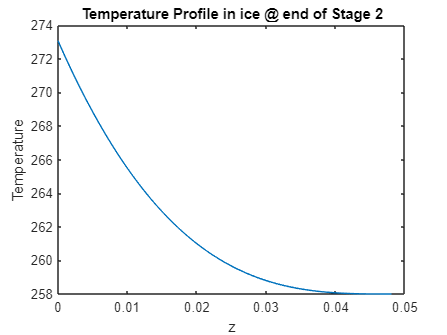

h_m_im = Ysol(:,1);
h_im = Ysol(:,2);
delta_im = Ysol(:,3);

locating_delta_im = delta_im - (H_0 + h_im - h_m_im); 
[~,idx_t2] = min(abs(locating_delta_im));

h_m_2 = Ysol(idx_t2,1);
h_2 = Ysol(idx_t2,2);
delta_2 = Ysol(idx_t2,3);

z_2_space_ice = linspace(0,delta_2,500);
h_2_space_water = linspace(0,h_2,50);

% Water and ice Temperature at end of t2
theta_z_t_2 = theta_t2_f(h_2,delta_2,z_2_space_ice);
T_z_t_2 = T_z_t_f(h_2,h_2_space_water);    

figure(2)
plot(z_2_space_ice,theta_z_t_2)
ylabel("Temperature")
xlabel("z")
title("Temperature Profile in ice @ end of Stage 2")

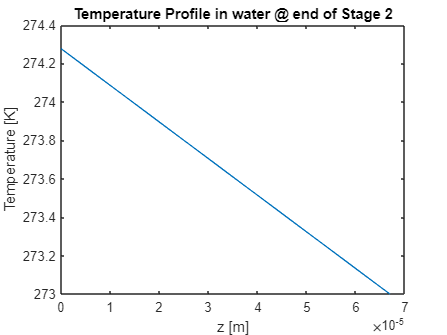


figure(3)
plot(h_2_space_water,T_z_t_2)
ylabel("Temperature [K]")
xlabel("z [m]")
title("Temperature Profile in water @ end of Stage 2")

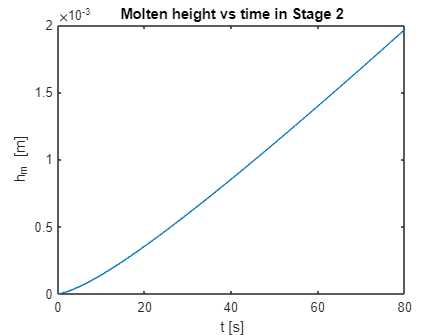


figure(4)
plot(tsol(1:idx_t2),Ysol(1:idx_t2,1))
ylabel("h_m [m]")
xlabel("t [s]")
title("Molten height vs time in Stage 2")

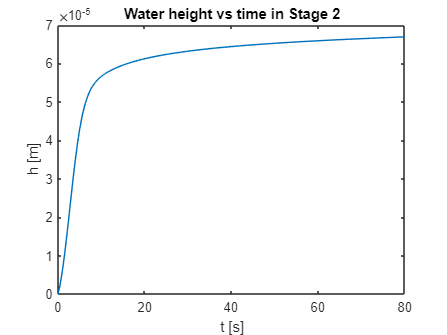


t2 = tsol(idx_t2);

figure(5)
plot(tsol(1:idx_t2),Ysol(1:idx_t2,2))
ylabel("h [m]")
xlabel("t [s]")
title("Water height vs time in Stage 2")

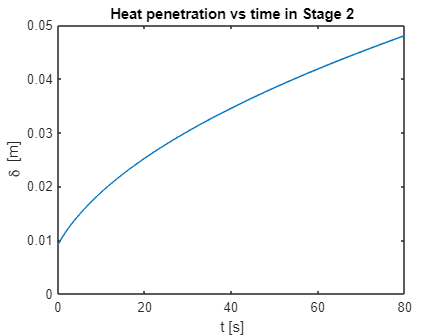


figure(6)
plot(tsol(1:idx_t2),Ysol(1:idx_t2,3))
ylabel("\delta [m]")
xlabel("t [s]")
title("Heat penetration vs time in Stage 2")

Stage 3 : Final Melting Stage

% 3rd stage starts when Theta_z_t_2(end) > 258 
r_end = 1650; % need to change r_end as per the melting time, if making it into a loop,...
% its taking a huge time, so better to manually edit after tracking u_max
tRange_fm = 0:t_step:r_end+t_step;
y0_fm =[h_m_2;h_2;0.25*(H_0-h_m_2)*(3*theta_0+T_m)];
opts = odeset('RelTol',1e-3); % can change tolerance to 1e-4 or 1e-5 but it can run into infinite loops, so be careful

[tsol_fm,Ysol_fm] = ode23s(@(t,Y) fm_ODEfun(t,Y,k_s,theta_0,L_m,h_sl,rho_s,rho_l,T_m,T_s,q,k_l,mu_l,H_0,L,alpha_s),tRange_fm,y0_fm,opts);   

h_m_fm =    0.001967840294424


h_fm =      6.691283971414102e-05


phi_fm =   12.572417802934494


dYdt = 3×1
   0.000028848904811
   0.000002984209423
  -0.006401008712995


h_m_fm =    0.001967840323747


h_fm =      6.691283971414102e-05


phi_fm =   12.572417802934494


dYdt = 3×1
   0.000028848904901
   0.000002984209522
  -0.006401008758155


h_m_fm =    0.001967840294424


h_fm =      6.691284071122003e-05


phi_fm =   12.572417802934494


dYdt = 3×1
   0.000028848904762
   0.000002984208194
  -0.006401008682101


h_m_fm =    0.001967840294424


h_fm =      6.691283971414102e-05


phi_fm =   12.572417615590869


dYdt = 3×1
   0.000028848902499
   0.000002984207303
  -0.006401007573422


h_m_fm =    0.001967840294424


h_fm =      6.691283971414102e-05


phi_fm =   12.572417802934494


dYdt = 3×1
   0.000028848904811
   0.000002984209423
  -0.006401008712995


h_m_fm =    0.001967840294424


h_fm =      6.691283971414102e-05


phi_fm =   12.572417802934494


dYdt = 3×1
   0.000028848904811
   0.000002984209423
  -0.006401008712995


h_m_fm =    0.001975048410243


h_fm =      6.754557771683183e-05


phi_fm =   12.570820219271152


dYdt = 3×1
   0.000028820864676
   0.000002203482231
  -0.006382695699240


h_m_fm =    0.001982251713727


h_fm =      6.803962423230779e-05


phi_fm =   12.569225824010127


dYdt = 3×1
   0.000028799596680
   0.000001585592678
  -0.006368587854196


h_m_fm =    0.001982251743265


h_fm =      6.803962423230779e-05


phi_fm =   12.569225824010127


dYdt = 3×1
   0.000028799596772
   0.000001585592779
  -0.006368587900018


h_m_fm =    0.001982251713727


h_fm =      6.803962524617720e-05


phi_fm =   12.569225824010127


dYdt = 3×1
   0.000028799596631
   0.000001585591388
  -0.006368587822237


h_m_fm =    0.001982251713727


h_fm =      6.803962423230779e-05


phi_fm =   12.569225636714068


dYdt = 3×1
   0.000028799594367
   0.000001585590558
  -0.006368586707248


h_m_fm =    0.001982251713727


h_fm =      6.803962423230779e-05


phi_fm =   12.569225824010127


dYdt = 3×1
   0.000028799596680
   0.000001585592678
  -0.006368587854196


h_m_fm =    0.002005740329074


h_fm =      6.885054919429885e-05


phi_fm =   12.564038436819864


dYdt = 3×1
   0.000028769115644
   0.000000563772350
  -0.006347569896793


h_m_fm =    0.002029218484352


h_fm =      6.922522839959732e-05


phi_fm =   12.558858792588216


dYdt = 3×1
   0.000028759780663
   0.000000095963466
  -0.006340352025357


h_m_fm =    0.002029218514590


h_fm =      6.922522839959732e-05


phi_fm =   12.558858792588216


dYdt = 3×1
   0.000028759780757
   0.000000095963571
  -0.006340352072697


h_m_fm =    0.002029218484352


h_fm =      6.922522943113361e-05


phi_fm =   12.558858792588216


dYdt = 3×1
   0.000028759780613
   0.000000095962111
  -0.006340351992309


h_m_fm =    0.002029218484352


h_fm =      6.922522839959732e-05


phi_fm =   12.558858605446638


dYdt = 3×1
   0.000028759778348
   0.000000095961343
  -0.006340350869697


h_m_fm =    0.002029218484352


h_fm =      6.922522839959732e-05


phi_fm =   12.558858792588216


dYdt = 3×1
   0.000028759780663
   0.000000095963466
  -0.006340352025357


h_m_fm =    0.002068389653510


h_fm =      6.930352115571476e-05


phi_fm =   12.550220691254738


dYdt = 3×1
   0.000028770621510
   0.000000030290318
  -0.006345842565882


h_m_fm =    0.002107574449881


h_fm =      6.934562849659039e-05


phi_fm =   12.541575463264179


dYdt = 3×1
   0.000028783214131
   0.000000012237211
  -0.006352499928648


h_m_fm =    0.002107574481286


h_fm =      6.934562849659039e-05


phi_fm =   12.541575463264179


dYdt = 3×1
   0.000028783214228
   0.000000012237320
  -0.006352499978015


h_m_fm =    0.002107574449881


h_fm =      6.934562952992078e-05


phi_fm =   12.541575463264179


dYdt = 3×1
   0.000028783214081
   0.000000012235851
  -0.006352499895629


h_m_fm =    0.002107574449881


h_fm =      6.934562849659039e-05


phi_fm =   12.541575276380142


dYdt = 3×1
   0.000028783211811
   0.000000012235084
  -0.006352498770468


h_m_fm =    0.002107574449881


h_fm =      6.934562849659039e-05


phi_fm =   12.541575463264179


dYdt = 3×1
   0.000028783214131
   0.000000012237211
  -0.006352499928648


h_m_fm =    0.002243481245584


h_fm =      6.943506073833153e-05


phi_fm =   12.511540512239577


dYdt = 3×1
   0.000028829428006
   0.000000024198590
  -0.006377307975562


h_m_fm =    0.002379567390342


h_fm =      6.953487159867921e-05


phi_fm =   12.481409464710939


dYdt = 3×1
   0.000028875188432
   0.000000023007402
  -0.006401811461579


h_m_fm =    0.002379567425800


h_fm =      6.953487159867921e-05


phi_fm =   12.481409464710939


dYdt = 3×1
   0.000028875188544
   0.000000023007526
  -0.006401811518025


h_m_fm =    0.002379567390342


h_fm =      6.953487263482954e-05


phi_fm =   12.481409464710939


dYdt = 3×1
   0.000028875188383
   0.000000023006038
  -0.006401811428888


h_m_fm =    0.002379567390342


h_fm =      6.953487159867921e-05


phi_fm =   12.481409278723445


dYdt = 3×1
   0.000028875186097
   0.000000023005260
  -0.006401810296124


h_m_fm =    0.002379567390342


h_fm =      6.953487159867921e-05


phi_fm =   12.481409464710939


dYdt = 3×1
   0.000028875188432
   0.000000023007402
  -0.006401811461579


h_m_fm =    0.002983462488755


h_fm =      6.997010829954832e-05


phi_fm =   12.346776684077676


dYdt = 3×1
   0.000029075181150
   0.000000029056724
  -0.006509072987988


h_m_fm =    0.003590812168871


h_fm =      7.041870135362455e-05


phi_fm =   12.210291738152973


dYdt = 3×1
   0.000029275417057
   0.000000027875647
  -0.006616420377978


h_m_fm =    0.003590812222379


h_fm =      7.041870135362455e-05


phi_fm =   12.210291738152973


dYdt = 3×1
   0.000029275417236
   0.000000027875845
  -0.006616420468143


h_m_fm =    0.003590812168871


h_fm =      7.041870240294497e-05


phi_fm =   12.210291738152973


dYdt = 3×1
   0.000029275417006
   0.000000027874267
  -0.006616420346686


h_m_fm =    0.003590812168871


h_fm =      7.041870135362455e-05


phi_fm =   12.210291556205448


dYdt = 3×1
   0.000029275414652
   0.000000027873441
  -0.006616419179152


h_m_fm =    0.003590812168871


h_fm =      7.041870135362455e-05


phi_fm =   12.210291738152973


dYdt = 3×1
   0.000029275417057
   0.000000027875647
  -0.006616420377978


h_m_fm =    0.004926471865158


h_fm =      7.138278640593229e-05


phi_fm =   11.905158529535267


dYdt = 3×1
   0.000029697842862
   0.000000064541373
  -0.006843588923137


h_m_fm =    0.006277979328421


h_fm =      7.242318495054421e-05


phi_fm =   11.591512974379834


dYdt = 3×1
   0.000030120173009
   0.000000054897313
  -0.007070425067925


h_m_fm =    0.006277979421971


h_fm =      7.242318495054421e-05


phi_fm =   11.591512974379834


dYdt = 3×1
   0.000030120173368
   0.000000054897706
  -0.007070425247292


h_m_fm =    0.006277979328421


h_fm =      7.242318602973377e-05


phi_fm =   11.591512974379834


dYdt = 3×1
   0.000030120172958
   0.000000054895898
  -0.007070425039548


h_m_fm =    0.006277979328421


h_fm =      7.242318495054421e-05


phi_fm =   11.591512801652831


dYdt = 3×1
   0.000030120170437
   0.000000054894953
  -0.007070423790247


h_m_fm =    0.006277979328421


h_fm =      7.242318495054421e-05


phi_fm =   11.591512974379834


dYdt = 3×1
   0.000030120173009
   0.000000054897313
  -0.007070425067925


h_m_fm =    0.007952452168779


h_fm =      7.370245211173999e-05


phi_fm =   11.194086907295780


dYdt = 3×1
   0.000030603807253
   0.000000079592564
  -0.007331396882251


h_m_fm =    0.009649013312719


h_fm =      7.507334916241319e-05


phi_fm =   10.784756723677893


dYdt = 3×1
   0.000031086161554
   0.000000077558031
  -0.007591293381163


h_m_fm =    0.009649013456500


h_fm =      7.507334916241319e-05


phi_fm =   10.784756723677893


dYdt = 3×1
   0.000031086162212
   0.000000077558746
  -0.007591293707661


h_m_fm =    0.009649013312719


h_fm =      7.507335028109327e-05


phi_fm =   10.784756723677893


dYdt = 3×1
   0.000031086161501
   0.000000077556577
  -0.007591293356002


h_m_fm =    0.009649013312719


h_fm =      7.507334916241319e-05


phi_fm =   10.784756562972493


dYdt = 3×1
   0.000031086158744
   0.000000077555454
  -0.007591291993148


h_m_fm =    0.009649013312719


h_fm =      7.507334916241319e-05


phi_fm =   10.784756723677893


dYdt = 3×1
   0.000031086161554
   0.000000077558031
  -0.007591293381163


h_m_fm =    0.011636924608512


h_fm =      7.669329079072465e-05


phi_fm =   10.294308082624843


dYdt = 3×1
   0.000031590842980
   0.000000107178197
  -0.007864888281538


h_m_fm =    0.013651211176140


h_fm =      7.844957408252503e-05


phi_fm =    9.789582445532430


dYdt = 3×1
   0.000032087677604
   0.000000108292051
  -0.008133857290842


h_m_fm =    0.013651211379559


h_fm =      7.844957408252503e-05


phi_fm =    9.789582445532430


dYdt = 3×1
   0.000032087678769
   0.000000108293299
  -0.008133857863184


h_m_fm =    0.013651211176140


h_fm =      7.844957525151478e-05


phi_fm =    9.789582445532430


dYdt = 3×1
   0.000032087677549
   0.000000108290555
  -0.008133857268805


h_m_fm =    0.013651211176140


h_fm =      7.844957408252503e-05


phi_fm =    9.789582299656283


dYdt = 3×1
   0.000032087674461
   0.000000108289168
  -0.008133855750543


h_m_fm =    0.013651211176140


h_fm =      7.844957408252503e-05


phi_fm =    9.789582445532430


dYdt = 3×1
   0.000032087677604
   0.000000108292051
  -0.008133857290842


h_m_fm =    0.015955938787250


h_fm =      8.050676369495064e-05


phi_fm =    9.200247489554455


dYdt = 3×1
   0.000032567359729
   0.000000146322643
  -0.008396359676673


h_m_fm =    0.018288456323836


h_fm =      8.277212798662504e-05


phi_fm =    8.595712770756030


dYdt = 3×1
   0.000033023431454
   0.000000152985624
  -0.008646403645629


h_m_fm =    0.018288456596355


h_fm =      8.277212798662504e-05


phi_fm =    8.595712770756030


dYdt = 3×1
   0.000033023433530
   0.000000152987812
  -0.008646404653256


h_m_fm =    0.018288456323836


h_fm =      8.277212922002586e-05


phi_fm =    8.595712770756030


dYdt = 3×1
   0.000033023431396
   0.000000152984091
  -0.008646403626190


h_m_fm =    0.018288456323836


h_fm =      8.277212798662504e-05


phi_fm =    8.595712642669929


dYdt = 3×1
   0.000033023427827
   0.000000152982299
  -0.008646401888399


h_m_fm =    0.018288456323836


h_fm =      8.277212798662504e-05


phi_fm =    8.595712770756030


dYdt = 3×1
   0.000033023431454
   0.000000152985624
  -0.008646403645629


h_m_fm =    0.020943243255104


h_fm =      8.546826372840827e-05


phi_fm =    7.896040657748005


dYdt = 3×1
   0.000033411792601
   0.000000209236415
  -0.008865538969791


h_m_fm =    0.023622284131210


h_fm =      8.850937045940678e-05


phi_fm =    7.182585746900570


dYdt = 3×1
   0.000033743313005
   0.000000228837725
  -0.009056955710889


h_m_fm =    0.023622284483209


h_fm =      8.850937045940678e-05


phi_fm =    7.182585746900570


dYdt = 3×1
   0.000033743316917
   0.000000228841760
  -0.009056957578874


h_m_fm =    0.023622284131210


h_fm =      8.850937177829918e-05


phi_fm =    7.182585746900570


dYdt = 3×1
   0.000033743312945
   0.000000228836164
  -0.009056955693033


h_m_fm =    0.023622284131210


h_fm =      8.850937045940678e-05


phi_fm =    7.182585639871702


dYdt = 3×1
   0.000033743308626
   0.000000228833709
  -0.009056953620556


h_m_fm =    0.023622284131210


h_fm =      8.850937045940678e-05


phi_fm =    7.182585746900570


dYdt = 3×1
   0.000033743313005
   0.000000228837725
  -0.009056955710889


h_m_fm =    0.026288992852180


h_fm =      9.183704006984731e-05


phi_fm =    6.464344365497784


dYdt = 3×1
   0.000033906565607
   0.000000226623065
  -0.009167598485198


h_m_fm =    0.028964361018859


h_fm =      9.557265749991537e-05


phi_fm =    5.739779760060710


dYdt = 3×1
   0.000033992077616
   0.000000294708936
  -0.009242606862340


h_m_fm =    0.028964361450462


h_fm =      9.557265749991537e-05


phi_fm =    5.739779760060710


dYdt = 3×1
   0.000033992085189
   0.000000294716573
  -0.009242610415682


h_m_fm =    0.028964361018859


h_fm =      9.557265892405894e-05


phi_fm =    5.739779760060710


dYdt = 3×1
   0.000033992077552
   0.000000294707365
  -0.009242606844624


h_m_fm =    0.028964361018859


h_fm =      9.557265749991537e-05


phi_fm =    5.739779674531326


dYdt = 3×1
   0.000033992072113
   0.000000294703890
  -0.009242604280553


h_m_fm =    0.028964361018859


h_fm =      9.557265749991537e-05


phi_fm =    5.739779760060710


dYdt = 3×1
   0.000033992077616
   0.000000294708936
  -0.009242606862340


h_m_fm =    0.031448835745134


h_fm =      9.962219785758019e-05


phi_fm =    5.063512232872592


dYdt = 3×1
   0.000033922169140
   0.000000255732389
  -0.009245555722946


h_m_fm =    0.033927308688619


h_fm =      1.042109924349526e-04


phi_fm =    4.387741830997921


dYdt = 3×1
   0.000033787486746
   0.000000394195814
  -0.009221850660732


h_m_fm =    0.033927309194176


h_fm =      1.042109924349526e-04


phi_fm =    4.387741830997921


dYdt = 3×1
   0.000033787501956
   0.000000394210812
  -0.009221857674306


h_m_fm =    0.033927308688619


h_fm =      1.042109939878174e-04


phi_fm =    4.387741830997921


dYdt = 3×1
   0.000033787486678
   0.000000394194253
  -0.009221850642132


h_m_fm =    0.033927308688619


h_fm =      1.042109924349526e-04


phi_fm =    4.387741765615473


dYdt = 3×1
   0.000033787479540
   0.000000394189206
  -0.009221847338059


h_m_fm =    0.033927308688619


h_fm =      1.042109924349526e-04


phi_fm =    4.387741830997921


dYdt = 3×1
   0.000033787486746
   0.000000394195814
  -0.009221850660732


h_m_fm =    0.036042944971254


h_fm =      1.091266054936740e-04


phi_fm =    3.810260147424203


dYdt = 3×1
   0.000033582349310
   0.000000283787174
  -0.009167552718476


h_m_fm =    0.038146855470441


h_fm =      1.146918225294790e-04


phi_fm =    3.235911503865269


dYdt = 3×1
   0.000033346080665
   0.000000515853859
  -0.009103591913946


h_m_fm =    0.035618632688503


h_fm =      1.082452022021190e-04


phi_fm =    3.926084616874922


dYdt = 3×1
   0.000033618924433
   0.000000132855803
  -0.009177234439765


h_m_fm =    0.037302745182173


h_fm =      1.124329703169753e-04


phi_fm =    3.466349557117451


dYdt = 3×1
   0.000033441963985
   0.000000311085052
  -0.009129623645344


h_m_fm =    0.037302745738027


h_fm =      1.124329703169753e-04


phi_fm =    3.466349557117451


dYdt = 3×1
   0.000033441990783
   0.000000311111076
  -0.009129635856559


h_m_fm =    0.037302745182173


h_fm =      1.124329719923571e-04


phi_fm =    3.466349557117451


dYdt = 3×1
   0.000033441963913
   0.000000311083499
  -0.009129623625712


h_m_fm =    0.037302745182173


h_fm =      1.124329703169753e-04


phi_fm =    3.466349505464817


dYdt = 3×1
   0.000033441954863
   0.000000311076687
  -0.009129619488843


h_m_fm =    0.037302745182173


h_fm =      1.124329703169753e-04


phi_fm =    3.466349557117451


dYdt = 3×1
   0.000033441963985
   0.000000311085052
  -0.009129623645344


h_m_fm =    0.038975325689128


h_fm =      1.175273714396681e-04


phi_fm =    3.009736018146402


dYdt = 3×1
   0.000033224873970
   0.000000368087683
  -0.009070387697174


h_m_fm =    0.040637797236377


h_fm =      1.235414788044859e-04


phi_fm =    2.555881411030308


dYdt = 3×1
   0.000032972040816
   0.000000563557056
  -0.009001370397984


h_m_fm =    0.038559395802526


h_fm =      1.163518994279036e-04


phi_fm =    3.123284718920095


dYdt = 3×1
   0.000033274718090
   0.000000191206363
  -0.009083989116394


h_m_fm =    0.039810584457116


h_fm =      1.205623850224411e-04


phi_fm =    2.781710477778727


dYdt = 3×1
   0.000033096807231
   0.000000315441750
  -0.009035430067493


h_m_fm =    0.039810585050340


h_fm =      1.205623850224411e-04


phi_fm =    2.781710477778727


dYdt = 3×1
   0.000033096851642
   0.000000315484383
  -0.009035450123904


h_m_fm =    0.039810584457116


h_fm =      1.205623868189606e-04


phi_fm =    2.781710477778727


dYdt = 3×1
   0.000033096807156
   0.000000315440209
  -0.009035430046873


h_m_fm =    0.039810584457116


h_fm =      1.205623850224411e-04


phi_fm =    2.781710436328011


dYdt = 3×1
   0.000033096795865
   0.000000315431327
  -0.009035424934107


h_m_fm =    0.039810584457116


h_fm =      1.205623850224411e-04


phi_fm =    2.781710477778727


dYdt = 3×1
   0.000033096807231
   0.000000315441750
  -0.009035430067493


h_m_fm =    0.041053275429463


h_fm =      1.255858920018533e-04


phi_fm =    2.442455785763417


dYdt = 3×1
   0.000032886930089
   0.000000353572574
  -0.008978130532856


h_m_fm =    0.042288723655489


h_fm =      1.314164540760216e-04


phi_fm =    2.105178467998066


dYdt = 3×1
   0.000032646687976
   0.000000516166210
  -0.008912547986357


h_m_fm =    0.040787578355449


h_fm =      1.245842675653934e-04


phi_fm =    2.514991098419939


dYdt = 3×1
   0.000032928565114
   0.000000224203506
  -0.008989497649781


h_m_fm =    0.041760246113565


h_fm =      1.289205415320715e-04


phi_fm =    2.249452824244974


dYdt = 3×1
   0.000032749100110
   0.000000335828202
  -0.008940505304937


h_m_fm =    0.041760246735841


h_fm =      1.289205415320715e-04


phi_fm =    2.249452824244974


dYdt = 3×1
   0.000032749171349
   0.000000335895976
  -0.008940537254312


h_m_fm =    0.041760246113565


h_fm =      1.289205434531373e-04


phi_fm =    2.249452824244974


dYdt = 3×1
   0.000032749100031
   0.000000335826674
  -0.008940505283349


h_m_fm =    0.041760246113565


h_fm =      1.289205415320715e-04


phi_fm =    2.249452790725515


dYdt = 3×1
   0.000032749086054
   0.000000335815312
  -0.008940499000976


h_m_fm =    0.041760246113565


h_fm =      1.289205415320715e-04


phi_fm =    2.249452824244974


dYdt = 3×1
   0.000032749100110
   0.000000335828202
  -0.008940505304937


h_m_fm =    0.042726217968534


h_fm =      1.340468989080088e-04


phi_fm =    1.985742472346075


dYdt = 3×1
   0.000032539415146
   0.000000375208312
  -0.008883258252795


h_m_fm =    0.043686534713267


h_fm =      1.399559308935293e-04


phi_fm =    1.723576051010252


dYdt = 3×1
   0.000032301074585
   0.000000526188363
  -0.008818196775942


h_m_fm =    0.042531786612095


h_fm =      1.330792456881369e-04


phi_fm =    2.038822240334473


dYdt = 3×1
   0.000032578790788
   0.000000264847021
  -0.008894008589521


h_m_fm =    0.043299827316876


h_fm =      1.375717900256961e-04


phi_fm =    1.829147158076509


dYdt = 3×1
   0.000032396820171
   0.000000369807283
  -0.008844333616676


h_m_fm =    0.043299827962093


h_fm =      1.375717900256961e-04


phi_fm =    1.829147158076509


dYdt = 3×1
   0.000032396931882
   0.000000369912807
  -0.008844383442556


h_m_fm =    0.043299827316876


h_fm =      1.375717920756755e-04


phi_fm =    1.829147158076509


dYdt = 3×1
   0.000032396820088
   0.000000369805769
  -0.008844333594132


h_m_fm =    0.043299827316876


h_fm =      1.375717900256961e-04


phi_fm =    1.829147130820092


dYdt = 3×1
   0.000032396802885
   0.000000369791432
  -0.008844325906669


h_m_fm =    0.043299827316876


h_fm =      1.375717900256961e-04


phi_fm =    1.829147158076509


dYdt = 3×1
   0.000032396820171
   0.000000369807283
  -0.008844333616676


h_m_fm =    0.044062471733161


h_fm =      1.428457033296030e-04


phi_fm =    1.620945187818677


dYdt = 3×1
   0.000032185724018
   0.000000413364233
  -0.008786698629342


h_m_fm =    0.044820590183793


h_fm =      1.488937712880898e-04


phi_fm =    1.413978917330565


dYdt = 3×1
   0.000031947102825
   0.000000559931728
  -0.008721565861502


h_m_fm =    0.044820590851672


h_fm =      1.488937712880898e-04


phi_fm =    1.413978917330565


dYdt = 3×1
   0.000031947296334
   0.000000560113223
  -0.008721651699442


h_m_fm =    0.044820590183793


h_fm =      1.488937735067799e-04


phi_fm =    1.413978917330565


dYdt = 3×1
   0.000031947102738
   0.000000559930238
  -0.008721565837776


h_m_fm =    0.044820590183793


h_fm =      1.488937712880898e-04


phi_fm =    1.413978896260637


dYdt = 3×1
   0.000031947080463
   0.000000559911223
  -0.008721555942183


h_m_fm =    0.044820590183793


h_fm =      1.488937712880898e-04


phi_fm =    1.413978917330565


dYdt = 3×1
   0.000031947102825
   0.000000559931728
  -0.008721565861502


h_m_fm =    0.045426964227444


h_fm =      1.549774651813434e-04


phi_fm =    1.248438724966678


dYdt = 3×1
   0.000031710461866
   0.000000460286615
  -0.008656946632636


h_m_fm =    0.046029377642444


h_fm =      1.616630738687660e-04


phi_fm =    1.083979955684943


dYdt = 3×1
   0.000031454669951
   0.000000655894217
  -0.008587140760420


h_m_fm =    0.046029378328335


h_fm =      1.616630738687660e-04


phi_fm =    1.083979955684943


dYdt = 3×1
   0.000031455008095
   0.000000656209615
  -0.008587290118808


h_m_fm =    0.046029377642444


h_fm =      1.616630762777335e-04


phi_fm =    1.083979955684943


dYdt = 3×1
   0.000031454669860
   0.000000655892748
  -0.008587140735447


h_m_fm =    0.046029377642444


h_fm =      1.616630738687660e-04


phi_fm =    1.083979939532383


dYdt = 3×1
   0.000031454640782
   0.000000655867468
  -0.008587127876355


h_m_fm =    0.046029377642444


h_fm =      1.616630738687660e-04


phi_fm =    1.083979955684943


dYdt = 3×1
   0.000031454669951
   0.000000655894217
  -0.008587140760420


h_m_fm =    0.046521253122273


h_fm =      1.685348065651511e-04


phi_fm =    0.949697838398324


dYdt = 3×1
   0.000031195639827
   0.000000622943044
  -0.008516386272499


h_m_fm =    0.047009502697499


h_fm =      1.762505401732185e-04


phi_fm =    0.816405845206520


dYdt = 3×1
   0.000030910485077
   0.000000851289113
  -0.008438605869402


h_m_fm =    0.046406658022194


h_fm =      1.670485099429627e-04


phi_fm =    0.980982318851283


dYdt = 3×1
   0.000031251302486
   0.000000499645192
  -0.008531590344240


h_m_fm =    0.046781871275163


h_fm =      1.726509415771514e-04


phi_fm =    0.878549183486260


dYdt = 3×1
   0.000031042904918
   0.000000637368897
  -0.008474732207485


h_m_fm =    0.046781871972268


h_fm =      1.726509415771514e-04


phi_fm =    0.878549183486260


dYdt = 3×1
   0.000031043428102
   0.000000637855243
  -0.008474962699344


h_m_fm =    0.046781871275163


h_fm =      1.726509441498509e-04


phi_fm =    0.878549183486260


dYdt = 3×1
   0.000031042904822
   0.000000637367443
  -0.008474732181508


h_m_fm =    0.046781871275163


h_fm =      1.726509415771514e-04


phi_fm =    0.878549170394857


dYdt = 3×1
   0.000031042868928
   0.000000637335895
  -0.008474716351939


h_m_fm =    0.046781871275163


h_fm =      1.726509415771514e-04


phi_fm =    0.878549183486260


dYdt = 3×1
   0.000031042904918
   0.000000637368897
  -0.008474732207485


h_m_fm =    0.047153937767945


h_fm =      1.791610782843981e-04


phi_fm =    0.776974933192959


dYdt = 3×1
   0.000030803664110
   0.000000755536073
  -0.008409367342132


h_m_fm =    0.047523384219547


h_fm =      1.866743883517949e-04


phi_fm =    0.676116187252992


dYdt = 3×1
   0.000030533013997
   0.000000955916164
  -0.008335573987859


h_m_fm =    0.047070632649754


h_fm =      1.777516139030272e-04


phi_fm =    0.799717245808506


dYdt = 3×1
   0.000030855142500
   0.000000651689524
  -0.008423431275480


h_m_fm =    0.047357862016737


h_fm =      1.833140304493580e-04


phi_fm =    0.721303713261276


dYdt = 3×1
   0.000030653534529
   0.000000773225022
  -0.008368444720229


h_m_fm =    0.047357862722424


h_fm =      1.833140304493580e-04


phi_fm =    0.721303713261276


dYdt = 3×1
   0.000030654320244
   0.000000773953503
  -0.008368790176053


h_m_fm =    0.047357862016737


h_fm =      1.833140331809499e-04


phi_fm =    0.721303713261276


dYdt = 3×1
   0.000030653534431
   0.000000773223588
  -0.008368444693336


h_m_fm =    0.047357862016737


h_fm =      1.833140304493580e-04


phi_fm =    0.721303702513013


dYdt = 3×1
   0.000030653490694
   0.000000773184825
  -0.008368425446948


h_m_fm =    0.047357862016737


h_fm =      1.833140304493580e-04


phi_fm =    0.721303713261276


dYdt = 3×1
   0.000030653534529
   0.000000773225022
  -0.008368444720229


h_m_fm =    0.047642754439872


h_fm =      1.897294439906621e-04


phi_fm =    0.643527980099126


dYdt = 3×1
   0.000030423429868
   0.000000867071060
  -0.008305547108617


h_m_fm =    0.047925723402966


h_fm =      1.969827547771218e-04


phi_fm =    0.566277589812678


dYdt = 3×1
   0.000030168735737
   0.000001061953513
  -0.008236151333852


h_m_fm =    0.047925724117114


h_fm =      1.969827547771218e-04


phi_fm =    0.566277589812678


dYdt = 3×1
   0.000030170025825
   0.000001063146544
  -0.008236717425715


h_m_fm =    0.047925723402966


h_fm =      1.969827577123936e-04


phi_fm =    0.566277589812678


dYdt = 3×1
   0.000030168735635
   0.000001061952109
  -0.008236151305860


h_m_fm =    0.047925723402966


h_fm =      1.969827547771218e-04


phi_fm =    0.566277581374484


dYdt = 3×1
   0.000030168679901
   0.000001061902311
  -0.008236126832810


h_m_fm =    0.047925723402966


h_fm =      1.969827547771218e-04


phi_fm =    0.566277589812678


dYdt = 3×1
   0.000030168735737
   0.000001061953513
  -0.008236151333852


h_m_fm =    0.048159210757261


h_fm =      2.042761253222937e-04


phi_fm =    0.502535376489001


dYdt = 3×1
   0.000029914853093
   0.000001107838457
  -0.008166634254331


h_m_fm =    0.048390960220072


h_fm =      2.123703363042836e-04


phi_fm =    0.439267975979523


dYdt = 3×1
   0.000029641394525
   0.000001347532291
  -0.008092311426833


h_m_fm =    0.048390960941154


h_fm =      2.123703363042836e-04


phi_fm =    0.439267975979523


dYdt = 3×1
   0.000029643559310
   0.000001349530079
  -0.008093259831374


h_m_fm =    0.048390960220072


h_fm =      2.123703394688482e-04


phi_fm =    0.439267975979523


dYdt = 3×1
   0.000029641394418
   0.000001347530920
  -0.008092311397703


h_m_fm =    0.048390960220072


h_fm =      2.123703363042836e-04


phi_fm =    0.439267969433920


dYdt = 3×1
   0.000029641322544
   0.000001347466285
  -0.008092279891629


h_m_fm =    0.048390960220072


h_fm =      2.123703363042836e-04


phi_fm =    0.439267975979523


dYdt = 3×1
   0.000029641394525
   0.000001347532291
  -0.008092311426833


h_m_fm =    0.048582666019833


h_fm =      2.205174773347136e-04


phi_fm =    0.386932051780700


dYdt = 3×1
   0.000029366159887
   0.000001463781490
  -0.008016670099028


h_m_fm =    0.048772792843866


h_fm =      2.296675408055029e-04


phi_fm =    0.335027728336463


dYdt = 3×1
   0.000029071434447
   0.000001777674683
  -0.007937045060497


h_m_fm =    0.048772793570637


h_fm =      2.296675408055029e-04


phi_fm =    0.335027728336463


dYdt = 3×1
   0.000029075185267
   0.000001781130349
  -0.007938686202996


h_m_fm =    0.048772792843866


h_fm =      2.296675442278160e-04


phi_fm =    0.335027728336463


dYdt = 3×1
   0.000029071434336
   0.000001777673352
  -0.007937045030198


h_m_fm =    0.048772792843866


h_fm =      2.296675408055029e-04


phi_fm =    0.335027723344161


dYdt = 3×1
   0.000029071340070
   0.000001777588140
  -0.007937003766608


h_m_fm =    0.048772792843866


h_fm =      2.296675408055029e-04


phi_fm =    0.335027728336463


dYdt = 3×1
   0.000029071434447
   0.000001777674683
  -0.007937045060497


h_m_fm =    0.048924381345481


h_fm =      2.386283639147608e-04


phi_fm =    0.293643710093066


dYdt = 3×1
   0.000028775915135
   0.000001943439518
  -0.007855086474261


h_m_fm =    0.049074622952164


h_fm =      2.486906875835692e-04


phi_fm =    0.252628196272132


dYdt = 3×1
   0.000028472749661
   0.000002342017282
  -0.007774491334973


h_m_fm =    0.049074623025291


h_fm =      2.486906875835692e-04


phi_fm =    0.252628196272132


dYdt = 3×1
   0.000028473413411
   0.000002342628005
  -0.007774781463726


h_m_fm =    0.049074622952164


h_fm =      2.486906912893492e-04


phi_fm =    0.252628196272132


dYdt = 3×1
   0.000028472749546
   0.000002342015999
  -0.007774491303514


h_m_fm =    0.049074622952164


h_fm =      2.486906875835692e-04


phi_fm =    0.252628192507679


dYdt = 3×1
   0.000028472624502
   0.000002341902511
  -0.007774436626826


h_m_fm =    0.049074622952164


h_fm =      2.486906875835692e-04


phi_fm =    0.252628196272132


dYdt = 3×1
   0.000028472749661
   0.000002342017282
  -0.007774491334973


h_m_fm =    0.049194870901556


h_fm =      2.585601920599638e-04


phi_fm =    0.219800020587861


dYdt = 3×1
   0.000028150595512
   0.000002601299678
  -0.007683504853655


h_m_fm =    0.049313960948718


h_fm =      2.697041650086173e-04


phi_fm =    0.187288956478910


dYdt = 3×1
   0.000027843133110
   0.000003132712631
  -0.007604102573113


h_m_fm =    0.049313961022202


h_fm =      2.697041650086173e-04


phi_fm =    0.187288956478910


dYdt = 3×1
   0.000027844346658
   0.000003133828101
  -0.007604632611688


h_m_fm =    0.049313960948718


h_fm =      2.697041690275226e-04


phi_fm =    0.187288956478910


dYdt = 3×1
   0.000027843132990
   0.000003132711407
  -0.007604102540511


h_m_fm =    0.049313960948718


h_fm =      2.697041650086173e-04


phi_fm =    0.187288953688087


dYdt = 3×1
   0.000027842964285
   0.000003132557819
  -0.007604028836078


h_m_fm =    0.049313960948718


h_fm =      2.697041650086173e-04


phi_fm =    0.187288956478910


dYdt = 3×1
   0.000027843133110
   0.000003132712631
  -0.007604102573113


h_m_fm =    0.049409340313524


h_fm =      2.806612231354557e-04


phi_fm =    0.161249825658416


dYdt = 3×1
   0.000027481492326
   0.000003510067086
  -0.007498858563245


h_m_fm =    0.049503718661981


h_fm =      2.930912506555633e-04


phi_fm =    0.135485204844219


dYdt = 3×1
   0.000027193409769
   0.000004250349629
  -0.007431352975364


h_m_fm =    0.049503718735747


h_fm =      2.930912506555633e-04


phi_fm =    0.135485204844219


dYdt = 3×1
   0.000027195737689
   0.000004252487741
  -0.007432369128669


h_m_fm =    0.049503718661981


h_fm =      2.930912550229633e-04


phi_fm =    0.135485204844219


dYdt = 3×1
   0.000027193409645
   0.000004250348480
  -0.007431352941640


h_m_fm =    0.049503718661981


h_fm =      2.930912506555633e-04


phi_fm =    0.135485202825332


dYdt = 3×1
   0.000027193176392
   0.000004250135623
  -0.007431251104985


h_m_fm =    0.049503718661981


h_fm =      2.930912506555633e-04


phi_fm =    0.135485204844219


dYdt = 3×1
   0.000027193409769
   0.000004250349629
  -0.007431352975364


h_m_fm =    0.049579767138731


h_fm =      3.054209192882968e-04


phi_fm =    0.114723184585254


dYdt = 3×1
   0.000026740575765
   0.000004765701369
  -0.007289993974264


h_m_fm =    0.049654932537039


h_fm =      3.194896763236945e-04


phi_fm =    0.094204077359662


dYdt = 3×1
   0.000026578321155
   0.000005905868268
  -0.007281652259050


h_m_fm =    0.049654932544438


h_fm =      3.194896763236945e-04


phi_fm =    0.094204077359662


dYdt = 3×1
   0.000026578804151
   0.000005906311619
  -0.007281862994292


h_m_fm =    0.049654932537039


h_fm =      3.194896810844617e-04


phi_fm =    0.094204077359662


dYdt = 3×1
   0.000026578321027
   0.000005905867217
  -0.007281652224232


h_m_fm =    0.049654932537039


h_fm =      3.194896763236945e-04


phi_fm =    0.094204075955912


dYdt = 3×1
   0.000026577985508
   0.000005905560480
  -0.007281505813715


h_m_fm =    0.049654932537039


h_fm =      3.194896763236945e-04


phi_fm =    0.094204077359662


dYdt = 3×1
   0.000026578321155
   0.000005905868268
  -0.007281652259050


h_m_fm =    0.049715757963377


h_fm =      3.335896431531159e-04


phi_fm =    0.077597401059159


dYdt = 3×1
   0.000025810242298
   0.000006458260399
  -0.007007372903277


h_m_fm =    0.049775783890494


h_fm =      3.497866559606574e-04


phi_fm =    0.061212372185683


dYdt = 3×1
   0.000026411309968
   0.000008730245348
  -0.007337274072796


h_m_fm =    0.049775783897911


h_fm =      3.497866559606574e-04


phi_fm =    0.061212372185683


dYdt = 3×1
   0.000026412456768
   0.000008731297546
  -0.007337774260838


h_m_fm =    0.049775783890494


h_fm =      3.497866611728847e-04


phi_fm =    0.061212372185683


dYdt = 3×1
   0.000026411309837
   0.000008730244429
  -0.007337274036918


h_m_fm =    0.049775783890494


h_fm =      3.497866559606574e-04


phi_fm =    0.061212371273547


dYdt = 3×1
   0.000026410793402
   0.000008729771656
  -0.007337048767104


h_m_fm =    0.049775783890494


h_fm =      3.497866559606574e-04


phi_fm =    0.061212372185683


dYdt = 3×1
   0.000026411309968
   0.000008730245348
  -0.007337274072796


h_m_fm =    0.049824430462825


h_fm =      3.661984599810900e-04


phi_fm =    0.047928943135240


dYdt = 3×1
   0.000023802835606
   0.000008092390538
  -0.006266098619498


h_m_fm =    0.049872317799020


h_fm =      3.851880033812307e-04


phi_fm =    0.034861343610950


dYdt = 3×1
   0.000031935273772
   0.000017944095750
  -0.009886630071945


h_m_fm =    0.049872317806452


h_fm =      3.851880033812307e-04


phi_fm =    0.034861343610950


dYdt = 3×1
   0.000031938817698
   0.000017947346309
  -0.009888175439037


h_m_fm =    0.049872317799020


h_fm =      3.851880091209793e-04


phi_fm =    0.034861343610950


dYdt = 3×1
   0.000031935273637
   0.000017944095016
  -0.009886630035070


h_m_fm =    0.049872317799020


h_fm =      3.851880033812307e-04


phi_fm =    0.034861343091475


dYdt = 3×1
   0.000031934366570
   0.000017943263845
  -0.009886234476508


h_m_fm =    0.049872317799020


h_fm =      3.851880033812307e-04


phi_fm =    0.034861343610950


dYdt = 3×1
   0.000031935273772
   0.000017944095750
  -0.009886630071945


h_m_fm =    0.049910983594462


h_fm =      4.046146766553269e-04


phi_fm =    0.024296128519731


dYdt = 3×1
   0.000005097729784
  -0.000004131960931
   0.001741964594342


h_m_fm =    0.049948759352509


h_fm =      4.271428413366878e-04


phi_fm =    0.014011450660764


dYdt = 3×1
   0.000270553194493
   0.000242743135632
  -0.114088455910114


h_m_fm =    0.049891696308861


h_fm =      3.945403739247989e-04


phi_fm =    0.029562823782695


dYdt = 3×1
   0.000014639370687
   0.000003250876258
  -0.002380477750160


h_m_fm =    0.049910805881221


h_fm =      4.044804734908681e-04


phi_fm =    0.024357094132459


dYdt = 3×1
   0.000049732055532
   0.000036787146603
  -0.017719040637839


h_m_fm =    0.049910805881965


h_fm =      4.044804734908681e-04


phi_fm =    0.024357094132459


dYdt = 3×1
   0.000049732782575
   0.000036787813392
  -0.017719357655194


h_m_fm =    0.049910805881221


h_fm =      4.044804795180968e-04


phi_fm =    0.024357094132459


dYdt = 3×1
   0.000049732055395
   0.000036787145981
  -0.017719040600525


h_m_fm =    0.049910805881221


h_fm =      4.044804734908681e-04


phi_fm =    0.024357093769510


dYdt = 3×1
   0.000049730756637
   0.000036785955516
  -0.017718474272492


h_m_fm =    0.049910805881221


h_fm =      4.044804734908681e-04


phi_fm =    0.024357094132459


dYdt = 3×1
   0.000049732055532
   0.000036787146603
  -0.017719040637839


h_m_fm =    0.049929863016526


h_fm =      4.156804617783660e-04


phi_fm =    0.019139400126694


dYdt = 3×1
  -0.000022208133562
  -0.000027615277665
   0.013606158461513


h_m_fm =    0.049948456120500


h_fm =      4.275794213751447e-04


phi_fm =    0.014092549301004


dYdt = 3×1
   0.000249606092488
   0.000223467833840
  -0.104955401686716


h_m_fm =    0.049948456121244


h_fm =      4.275794213751447e-04


phi_fm =    0.014092549301004


dYdt = 3×1
   0.000249608276465
   0.000223469836653
  -0.104956354079221


h_m_fm =    0.049948456120500


h_fm =      4.275794277465745e-04


phi_fm =    0.014092549301004


dYdt = 3×1
   0.000249606092349
   0.000223467833370
  -0.104955401649047


h_m_fm =    0.049948456120500


h_fm =      4.275794213751447e-04


phi_fm =    0.014092549091009


dYdt = 3×1
   0.000249603842106
   0.000223465770240
  -0.104954420335958


h_m_fm =    0.049948456120500


h_fm =      4.275794213751447e-04


phi_fm =    0.014092549301004


dYdt = 3×1
   0.000249606092488
   0.000223467833840
  -0.104955401686716


h_m_fm =    0.049976520482747


h_fm =      4.489380438101561e-04


phi_fm =    0.006372128999537


dYdt = 3×1
  -0.001927725871482
  -0.001769686407013
   0.843904784388549


h_m_fm =    0.049992256084570


h_fm =      4.622275692626486e-04


phi_fm =    0.002647647292535


dYdt = 3×1
   0.002533383818969
   0.002323118078202
  -1.123767393889487


h_m_fm =    0.049951485400286


h_fm =      4.297437134651081e-04


phi_fm =    0.013227438384212


dYdt = 3×1
  -0.000182447548737
  -0.000172400776827
   0.083410465355848


h_m_fm =    0.049954050871751


h_fm =      4.315119358589159e-04


phi_fm =    0.012555056457232


dYdt = 3×1
   0.000171309636316
   0.000152282203245
  -0.070825904877981


h_m_fm =    0.049949841816503


h_fm =      4.285900859558209e-04


phi_fm =    0.013677891498299


dYdt = 3×1
  -0.000149271917064
  -0.000142157423430
   0.068952659448929


h_m_fm =    0.049950865876886


h_fm =      4.292741122864112e-04


phi_fm =    0.013417691145465


dYdt = 3×1
   0.000071837768456
   0.000060712880665
  -0.027446087369791


h_m_fm =    0.049949167583902


h_fm =      4.281197444492368e-04


phi_fm =    0.013863415074588


dYdt = 3×1
  -0.000128635558326
  -0.000123306321851
   0.059958375432076


h_m_fm =    0.049949566637170


h_fm =      4.283745038636090e-04


phi_fm =    0.013769294864239


dYdt = 3×1
   0.000034839255216
   0.000026644131731
  -0.011311512218704


h_m_fm =    0.049948878249577


h_fm =      4.279166030258945e-04


phi_fm =    0.013944471672023


dYdt = 3×1
  -0.000104378103914
  -0.000101093072216
   0.049384410928200


h_m_fm =    0.049949031470857


h_fm =      4.280073866723616e-04


phi_fm =    0.013913188986200


dYdt = 3×1
1.0e-03 *

   0.010436431176211
   0.004209066500489
  -0.670811900905152


h_m_fm =    0.049948741471754


h_fm =      4.278175305846618e-04


phi_fm =    0.013985081693679


dYdt = 3×1
  -0.000068262626077
  -0.000067989555779
   0.033640314424840


h_m_fm =    0.049948811627832


h_fm =      4.278583562539448e-04


phi_fm =    0.013971278368804


dYdt = 3×1
  -0.000010392288350
  -0.000014914551427
   0.008410660468446


h_m_fm =    0.049948665691757


h_fm =      4.277592601637388e-04


phi_fm =    0.014010039038641


dYdt = 3×1
  -0.000021863003393
  -0.000025448875275
   0.013411963823570


h_m_fm =    0.049948718844405


h_fm =      4.277956821232059e-04


phi_fm =    0.013995671956505


dYdt = 3×1
  -0.000020403942643
  -0.000024105227012
   0.012775721992591


h_m_fm =    0.049948619604019


h_fm =      4.277217853194737e-04


phi_fm =    0.014026688705349


dYdt = 3×1
   0.000022088553914
   0.000014850088144
  -0.005749986391023


h_m_fm =    0.049948673394701


h_fm =      4.277635708204856e-04


phi_fm =    0.014008633827845


dYdt = 3×1
  -0.000014336656237
  -0.000018546338818
   0.010130652028975


h_m_fm =    0.049948593219003


h_fm =      4.276996355302449e-04


phi_fm =    0.014036722342492


dYdt = 3×1
   0.000052585705652
   0.000042813373134
  -0.019046568318278


h_m_fm =    0.049948648123318


h_fm =      4.277444841658001e-04


phi_fm =    0.014016722704207


dYdt = 3×1
  -0.000001453004335
  -0.000006734639305
   0.004513722285619


h_m_fm =    0.049948648122574


h_fm =      4.277444841658001e-04


phi_fm =    0.014016722704207


dYdt = 3×1
  -0.000001455197392
  -0.000006736650446
   0.004514678417430


h_m_fm =    0.049948648123318


h_fm =      4.277444777919106e-04


phi_fm =    0.014016722704207


dYdt = 3×1
  -0.000001453004197
  -0.000006734638837
   0.004513722247746


h_m_fm =    0.049948648123318


h_fm =      4.277444841658001e-04


phi_fm =    0.014016722913072


dYdt = 3×1
  -0.000001450749293
  -0.000006732571432
   0.004512739129521


h_m_fm =    0.049948648123318


h_fm =      4.277444841658001e-04


phi_fm =    0.014016722704207


dYdt = 3×1
  -0.000001453004335
  -0.000006734639305
   0.004513722285619


h_m_fm =    0.049948659790069


h_fm =      4.277496893979823e-04


phi_fm =    0.014015582367794


dYdt = 3×1
   0.000020621150414
   0.000013508758178
  -0.005110311572288


h_m_fm =    0.049948680538805


h_fm =      4.277632244994212e-04


phi_fm =    0.014010482225154


dYdt = 3×1
   0.000026718105612
   0.000019101922935
  -0.007768578923842


h_m_fm =    0.049948680538879


h_fm =      4.277632244994212e-04


phi_fm =    0.014010482225154


dYdt = 3×1
   0.000026718325268
   0.000019102124370
  -0.007768674692401


h_m_fm =    0.049948680538805


h_fm =      4.277632308735900e-04


phi_fm =    0.014010482225154


dYdt = 3×1
   0.000026718105473
   0.000019101922467
  -0.007768578885991


h_m_fm =    0.049948680538805


h_fm =      4.277632244994212e-04


phi_fm =    0.014010482204276


dYdt = 3×1
   0.000026717879923
   0.000019101715978
  -0.007768480525287


h_m_fm =    0.049948680538805


h_fm =      4.277632244994212e-04


phi_fm =    0.014010482225154


dYdt = 3×1
   0.000026718105612
   0.000019101922935
  -0.007768578923842


h_m_fm =    0.049948724591043


h_fm =      4.277940496054298e-04


phi_fm =    0.013998158323030


dYdt = 3×1
   0.000023499329532
   0.000016154986865
  -0.006365328055760


h_m_fm =    0.049948766967687


h_fm =      4.278233449077127e-04


phi_fm =    0.013986564805221


dYdt = 3×1
   0.000023230333908
   0.000015912842870
  -0.006248152219985


h_m_fm =    0.049948766967761


h_fm =      4.278233449077127e-04


phi_fm =    0.013986564805221


dYdt = 3×1
   0.000023230554296
   0.000015913044976
  -0.006248248307176


h_m_fm =    0.049948766967687


h_fm =      4.278233512827773e-04


phi_fm =    0.013986564805221


dYdt = 3×1
   0.000023230333769
   0.000015912842402
  -0.006248152182131


h_m_fm =    0.049948766967687


h_fm =      4.278233449077127e-04


phi_fm =    0.013986564784380


dYdt = 3×1
   0.000023230107844
   0.000015912635569
  -0.006248053658013


h_m_fm =    0.049948766967687


h_fm =      4.278233449077127e-04


phi_fm =    0.013986564805221


dYdt = 3×1
   0.000023230333908
   0.000015912842870
  -0.006248152219985


h_m_fm =    0.049948886197844


h_fm =      4.279056166760924e-04


phi_fm =    0.013954091110399


dYdt = 3×1
   0.000024055567143
   0.000016682333678
  -0.006608238287657


h_m_fm =    0.049949005979215


h_fm =      4.279884472276959e-04


phi_fm =    0.013921375869398


dYdt = 3×1
   0.000023891525361
   0.000016544727049
  -0.006537011070211


h_m_fm =    0.049949005979290


h_fm =      4.279884472276959e-04


phi_fm =    0.013921375869398


dYdt = 3×1
   0.000023891747822
   0.000016544931057
  -0.006537108061130


h_m_fm =    0.049949005979215


h_fm =      4.279884536052208e-04


phi_fm =    0.013921375869398


dYdt = 3×1
   0.000023891525223
   0.000016544726583
  -0.006537011032354


h_m_fm =    0.049949005979215


h_fm =      4.279884472276959e-04


phi_fm =    0.013921375848654


dYdt = 3×1
   0.000023891298237
   0.000016544518776
  -0.006536912045821


h_m_fm =    0.049949005979215


h_fm =      4.279884472276959e-04


phi_fm =    0.013921375869398


dYdt = 3×1
   0.000023891525361
   0.000016544727049
  -0.006537011070211


h_m_fm =    0.049949454513672


h_fm =      4.282992065553590e-04


phi_fm =    0.013798912517392


dYdt = 3×1
   0.000023736535319
   0.000016450738110
  -0.006470537825026


h_m_fm =    0.049949902828091


h_fm =      4.286105177573257e-04


phi_fm =    0.013676527898334


dYdt = 3×1
   0.000023787906907
   0.000016546180949
  -0.006494037720484


h_m_fm =    0.049949902828165


h_fm =      4.286105177573257e-04


phi_fm =    0.013676527898334


dYdt = 3×1
   0.000023788137426
   0.000016546392345
  -0.006494138224307


h_m_fm =    0.049949902828091


h_fm =      4.286105241441201e-04


phi_fm =    0.013676527898334


dYdt = 3×1
   0.000023787906769
   0.000016546180487
  -0.006494037682615


h_m_fm =    0.049949902828091


h_fm =      4.286105177573257e-04


phi_fm =    0.013676527877954


dYdt = 3×1
   0.000023787675717
   0.000016545968947
  -0.006493936923547


h_m_fm =    0.049949902828091


h_fm =      4.286105177573257e-04


phi_fm =    0.013676527898334


dYdt = 3×1
   0.000023787906907
   0.000016546180949
  -0.006494037720484


h_m_fm =    0.049952142304161


h_fm =      4.301811407040090e-04


phi_fm =    0.013065150935833


dYdt = 3×1
   0.000023753865751
   0.000016759532205
  -0.006484748118695


h_m_fm =    0.049954379106265


h_fm =      4.317686935281170e-04


phi_fm =    0.012454504070696


dYdt = 3×1
   0.000023720993954
   0.000016979355956
  -0.006476012053470


h_m_fm =    0.049954379106339


h_fm =      4.317686935281170e-04


phi_fm =    0.012454504070696


dYdt = 3×1
   0.000023721271954
   0.000016979610893
  -0.006476133258131


h_m_fm =    0.049954379106265


h_fm =      4.317686999619719e-04


phi_fm =    0.012454504070696


dYdt = 3×1
   0.000023720993815
   0.000016979355516
  -0.006476012015541


h_m_fm =    0.049954379106265


h_fm =      4.317686935281170e-04


phi_fm =    0.012454504052138


dYdt = 3×1
   0.000023720740079
   0.000016979123153
  -0.006475901367068


h_m_fm =    0.049954379106265


h_fm =      4.317686935281170e-04


phi_fm =    0.012454504070696


dYdt = 3×1
   0.000023720993954
   0.000016979355956
  -0.006476012053470


h_m_fm =    0.049965504236670


h_fm =      4.400642980907376e-04


phi_fm =    0.009417343594028


dYdt = 3×1
   0.000023546996769
   0.000018149539691
  -0.006429129727165


h_m_fm =    0.049976557802406


h_fm =      4.488529350840908e-04


phi_fm =    0.006399719047747


dYdt = 3×1
   0.000023310219846
   0.000019422250128
  -0.006356128802861


h_m_fm =    0.049976557802480


h_fm =      4.488529350840908e-04


phi_fm =    0.006399719047747


dYdt = 3×1
   0.000023311273111
   0.000019423215984
  -0.006356588002907


h_m_fm =    0.049976557802406


h_fm =      4.488529417725207e-04


phi_fm =    0.006399719047747


dYdt = 3×1
   0.000023310219706
   0.000019422249814
  -0.006356128764630


h_m_fm =    0.049976557802406


h_fm =      4.488529350840908e-04


phi_fm =    0.006399719038210


dYdt = 3×1
   0.000023309725780
   0.000019421797069
  -0.006355913400953


h_m_fm =    0.049976557802406


h_fm =      4.488529350840908e-04


phi_fm =    0.006399719047747


dYdt = 3×1
   0.000023310219846
   0.000019422250128
  -0.006356128802861


h_m_fm =    0.050000511205229


h_fm =      4.708378134876099e-04


phi_fm =     -1.395562178861994e-04


dYdt = 3×1
   0.000329003698956
   0.000303695483665
  -0.139703804165342


h_m_fm =    0.050024182667071


h_fm =      4.965813627207989e-04


phi_fm =   -0.006622029038029


dYdt = 3×1
  -0.000959129949401
  -0.000872226627047
   0.421902281387660


h_m_fm =    0.049984987530076


h_fm =      4.561295026801432e-04


phi_fm =    0.004098405687476


dYdt = 3×1
   0.000023381865181
   0.000020751680573
  -0.006412033875954


h_m_fm =    0.049993370758500


h_fm =      4.637670474304507e-04


phi_fm =    0.001809774981861


dYdt = 3×1
   0.000017899579544
   0.000017112973071
  -0.004047451654792


h_m_fm =    0.049993370758574


h_fm =      4.637670474304507e-04


phi_fm =    0.001809774981861


dYdt = 3×1
   0.000017912754968
   0.000017125054949
  -0.004053195793454


h_m_fm =    0.049993370758500


h_fm =      4.637670543411182e-04


phi_fm =    0.001809774981861


dYdt = 3×1
   0.000017899579403
   0.000017112972876
  -0.004047451616326


h_m_fm =    0.049993370758500


h_fm =      4.637670474304507e-04


phi_fm =    0.001809774979164


dYdt = 3×1
   0.000017897832444
   0.000017111370981
  -0.004046689965192


h_m_fm =    0.049993370758500


h_fm =      4.637670474304507e-04


phi_fm =    0.001809774981861


dYdt = 3×1
   0.000017899579544
   0.000017112973071
  -0.004047451654792


h_m_fm =    0.050001684855684


h_fm =      4.719508856380262e-04


phi_fm =     -4.599400541744989e-04


dYdt = 3×1
   0.000279109389446
   0.000258167741446
  -0.117954612965637


h_m_fm =    0.050009959556100


h_fm =      4.805883471320319e-04


phi_fm =   -0.002720250131023


dYdt = 3×1
  -0.000347930257227
  -0.000315137512241
   0.155395296862029


h_m_fm =    0.049999362111549


h_fm =      4.696024842880660e-04


phi_fm =      1.741635266304729e-04


dYdt = 3×1
   0.001420900610502
   0.001304747780878
  -0.615743025399881


h_m_fm =    0.050005358247778


h_fm =      4.756886452797104e-04


phi_fm =   -0.001470120847822


dYdt = 3×1
  -0.007235225647651
  -0.006631750013167
   3.159183675473871


h_m_fm =    0.049994445662744


h_fm =      4.647904709339747e-04


phi_fm =    0.001516342261629


dYdt = 3×1
   0.000030586634830
   0.000028935363129
  -0.009582075145633


h_m_fm =    0.049995520025597


h_fm =      4.658207459287585e-04


phi_fm =    0.001223017506012


dYdt = 3×1
   0.000001010312997
   0.000002004678800
   0.003309005273527


h_m_fm =    0.049995520025628


h_fm =      4.658207459287585e-04


phi_fm =    0.001223017506012


dYdt = 3×1
   0.000001022257368
   0.000002015631794
   0.003303797850225


h_m_fm =    0.049995520025597


h_fm =      4.658207528700286e-04


phi_fm =    0.001223017506012


dYdt = 3×1
   0.000001010312856
   0.000002004678622
   0.003309005312023


h_m_fm =    0.049995520025597


h_fm =      4.658207459287585e-04


phi_fm =    0.001223017506194


dYdt = 3×1
   0.000001010571522
   0.000002004915868
   0.003308892563645


h_m_fm =    0.049995520025597


h_fm =      4.658207459287585e-04


phi_fm =    0.001223017506012


dYdt = 3×1
   0.000001010312997
   0.000002004678800
   0.003309005273527


h_m_fm =    0.049996592863766


h_fm =      4.668600973403619e-04


phi_fm =      9.301666380734845e-04


dYdt = 3×1
   0.000068226152585
   0.000063834693717
  -0.025998792353055


h_m_fm =    0.049997665541232


h_fm =      4.679068362881431e-04


phi_fm =      6.372507613577416e-04


dYdt = 3×1
  -0.000272116555465
  -0.000248063881598
   0.122377448027386


h_m_fm =    0.049997665541201


h_fm =      4.679068362881431e-04


phi_fm =      6.372507613577416e-04


dYdt = 3×1
  -0.000272160537562
  -0.000248104213186
   0.122396622827769


h_m_fm =    0.049997665541232


h_fm =      4.679068293157879e-04


phi_fm =      6.372507613577416e-04


dYdt = 3×1
  -0.000272116555324
  -0.000248063881437
   0.122377447988858


h_m_fm =    0.049997665541232


h_fm =      4.679068362881431e-04


phi_fm =      6.372507614526994e-04


dYdt = 3×1
  -0.000272116059376
  -0.000248063426685
   0.122377231748637


h_m_fm =    0.049997665541232


h_fm =      4.679068362881431e-04


phi_fm =      6.372507613577416e-04


dYdt = 3×1
  -0.000272116555465
  -0.000248063881598
   0.122377448027386


h_m_fm =    0.049999717668681


h_fm =      4.699396421076451e-04


phi_fm =      7.721579716040924e-05


dYdt = 3×1
   0.049794436325409
   0.045663346950589
 -21.708043086258556


h_m_fm =    0.049998692649086


h_fm =      4.691498202871969e-04


phi_fm =      3.245547349024952e-04


dYdt = 3×1
  -0.005388896562388
  -0.004941601586532
   2.334695585981894


h_m_fm =    0.049997870365287


h_fm =      4.681079816158476e-04


phi_fm =      5.814401156981920e-04


dYdt = 3×1
   0.000335827728395
   0.000309458693431
  -0.142670929190416


h_m_fm =    0.049998076042905


h_fm =      4.683101898887762e-04


phi_fm =      5.251920101145099e-04


dYdt = 3×1
  -0.000348363066809
  -0.000317906343232
   0.155617342091096


h_m_fm =    0.049998076042875


h_fm =      4.683101898887762e-04


phi_fm =      5.251920101145099e-04


dYdt = 3×1
  -0.000348427819038
  -0.000317965721032
   0.155645571996835


h_m_fm =    0.049998076042905


h_fm =      4.683101829104106e-04


phi_fm =      5.251920101145099e-04


dYdt = 3×1
  -0.000348363066667
  -0.000317906343075
   0.155617342052563


h_m_fm =    0.049998076042905


h_fm =      4.683101898887762e-04


phi_fm =      5.251920101927695e-04


dYdt = 3×1
  -0.000348362464876
  -0.000317905791260
   0.155617079667647


h_m_fm =    0.049998076042905


h_fm =      4.683101898887762e-04


phi_fm =      5.251920101145099e-04


dYdt = 3×1
  -0.000348363066809
  -0.000317906343232
   0.155617342091096


h_m_fm =    0.049998280895350


h_fm =      4.685120385471402e-04


phi_fm =      4.693599801288687e-04


dYdt = 3×1
   0.000450795079829
   0.000414959545517
  -0.192795404414224


h_m_fm =    0.049998486354246


h_fm =      4.687147248321545e-04


phi_fm =      4.131724927576056e-04


dYdt = 3×1
  -0.000633150995719
  -0.000578980926034
   0.279774531481987


h_m_fm =    0.049998486354216


h_fm =      4.687147248321545e-04


phi_fm =      4.131724927576056e-04


dYdt = 3×1
  -0.000633255603946
  -0.000579076851784
   0.279820137103018


h_m_fm =    0.049998486354246


h_fm =      4.687147178477608e-04


phi_fm =      4.131724927576056e-04


dYdt = 3×1
  -0.000633150995578
  -0.000578980925880
   0.279774531443448


h_m_fm =    0.049998486354246


h_fm =      4.687147248321545e-04


phi_fm =      4.131724928191731e-04


dYdt = 3×1
  -0.000633150230646
  -0.000578980224462
   0.279774197936036


h_m_fm =    0.049998486354246


h_fm =      4.687147248321545e-04


phi_fm =      4.131724927576056e-04


dYdt = 3×1
  -0.000633150995719
  -0.000578980926034
   0.279774531481987


h_m_fm =    0.049998730780099


h_fm =      4.689564206235287e-04


phi_fm =      3.465513223355325e-04


dYdt = 3×1
   0.000982437631761
   0.000902559276406
  -0.424582314491162


h_m_fm =    0.049998974816828


h_fm =      4.691981621020094e-04


phi_fm =      2.797727176699297e-04


dYdt = 3×1
  -0.002747979876192
  -0.002518188078370
   1.201754480377542


h_m_fm =    0.049998974816797


h_fm =      4.691981621020094e-04


phi_fm =      2.797727176699297e-04


dYdt = 3×1
  -0.002748207807934
  -0.002518397091784
   1.201853847570497


h_m_fm =    0.049998974816828


h_fm =      4.691981551104119e-04


phi_fm =      2.797727176699297e-04


dYdt = 3×1
  -0.002747979876051
  -0.002518188078220
   1.201754480338996


h_m_fm =    0.049998974816828


h_fm =      4.691981621020094e-04


phi_fm =      2.797727177116190e-04


dYdt = 3×1
  -0.002747978746856
  -0.002518187042768
   1.201753988041421


h_m_fm =    0.049998974816828


h_fm =      4.691981621020094e-04


phi_fm =      2.797727176699297e-04


dYdt = 3×1
  -0.002747979876192
  -0.002518188078370
   1.201754480377542


h_m_fm =    0.049999262835764


h_fm =      4.694840380715285e-04


phi_fm =      2.013757394486808e-04


dYdt = 3×1
   0.006828918866186
   0.006263881951219
  -2.973623813126541


h_m_fm =    0.049999506996839


h_fm =      4.697301843891004e-04


phi_fm =      1.340851892457860e-04


dYdt = 3×1
  -0.059094014975667
  -0.054187402556046
  25.760470877367389


h_m_fm =    0.049999044480707


h_fm =      4.692673006764506e-04


phi_fm =      2.609430080173968e-04


dYdt = 3×1
   0.002712217207943
   0.002488825662277
  -1.178743919784074


h_m_fm =    0.049999111777128


h_fm =      4.693342998990550e-04


phi_fm =      2.424201255737502e-04


dYdt = 3×1
  -0.002312597294050
  -0.002118916653334
   1.011950468223291


h_m_fm =    0.049999111777097


h_fm =      4.693342998990550e-04


phi_fm =      2.424201255737502e-04


dYdt = 3×1
  -0.002312900997357
  -0.002119195149272
   1.012082869955019


h_m_fm =    0.049999111777128


h_fm =      4.693342929054289e-04


phi_fm =      2.424201255737502e-04


dYdt = 3×1
  -0.002312597293909
  -0.002118916653185
   1.011950468184743


h_m_fm =    0.049999111777128


h_fm =      4.693342998990550e-04


phi_fm =      2.424201256098736e-04


dYdt = 3×1
  -0.002312595990446
  -0.002118915457929
   1.011949899907211


h_m_fm =    0.049999111777128


h_fm =      4.693342998990550e-04


phi_fm =      2.424201255737502e-04


dYdt = 3×1
  -0.002312597294050
  -0.002118916653334
   1.011950468223291


h_m_fm =    0.049999181625866


h_fm =      4.694036859296077e-04


phi_fm =      2.234720825644932e-04


dYdt = 3×1
   0.002401143522619
   0.002203596747461
  -1.043115572059657


h_m_fm =    0.049999249976576


h_fm =      4.694717313654650e-04


phi_fm =      2.047077478561036e-04


dYdt = 3×1
  -0.002439168891672
  -0.002234956933885
   1.067133048838708


h_m_fm =    0.049999249976545


h_fm =      4.694717313654650e-04


phi_fm =      2.047077478561036e-04


dYdt = 3×1
  -0.002439594852086
  -0.002235347539591
   1.067318750226223


h_m_fm =    0.049999249976576


h_fm =      4.694717243697910e-04


phi_fm =      2.047077478561036e-04


dYdt = 3×1
  -0.002439168891531
  -0.002234956933737
   1.067133048800158


h_m_fm =    0.049999249976576


h_fm =      4.694717313654650e-04


phi_fm =      2.047077478866074e-04


dYdt = 3×1
  -0.002439167347822
  -0.002234955518174
   1.067132375782825


h_m_fm =    0.049999249976576


h_fm =      4.694717313654650e-04


phi_fm =      2.047077478561036e-04


dYdt = 3×1
  -0.002439168891672
  -0.002234956933885
   1.067133048838708


h_m_fm =    0.049999316233157


h_fm =      4.695376146570323e-04


phi_fm =      1.867113276574222e-04


dYdt = 3×1
   0.002640193095104
   0.002422830429271
  -1.147335530191950


h_m_fm =    0.049999380901750


h_fm =      4.696020706931898e-04


phi_fm =      1.689716412536710e-04


dYdt = 3×1
  -0.003110348427626
  -0.002850404013643
   1.359743234481123


h_m_fm =    0.049999380901719


h_fm =      4.696020706931898e-04


phi_fm =      1.689716412536710e-04


dYdt = 3×1
  -0.003110973584939
  -0.002850977282905
   1.360015777147379


h_m_fm =    0.049999380901750


h_fm =      4.696020636955737e-04


phi_fm =      1.689716412536710e-04


dYdt = 3×1
  -0.003110348427485
  -0.002850404013496
   1.359743234442571


h_m_fm =    0.049999380901750


h_fm =      4.696020706931898e-04


phi_fm =      1.689716412788498e-04


dYdt = 3×1
  -0.003110346557310
  -0.002850402298563
   1.359742419100871


h_m_fm =    0.049999380901750


h_fm =      4.696020706931898e-04


phi_fm =      1.689716412536710e-04


dYdt = 3×1
  -0.003110348427626
  -0.002850404013643
   1.359743234481123


h_m_fm =    0.049999447801142


h_fm =      4.696686503447593e-04


phi_fm =      1.507892214001509e-04


dYdt = 3×1
   0.003658131837814
   0.003356304952637
  -1.591140551244292


h_m_fm =    0.049999511802224


h_fm =      4.697326019123828e-04


phi_fm =      1.332305369754694e-04


dYdt = 3×1
  -0.005645959938291
  -0.005175535177897
   2.465165164577432


h_m_fm =    0.049999511802194


h_fm =      4.697326019123828e-04


phi_fm =      1.332305369754694e-04


dYdt = 3×1
  -0.005646965073092
  -0.005176456886516
   2.465603355201023


h_m_fm =    0.049999511802224


h_fm =      4.697325949128216e-04


phi_fm =      1.332305369754694e-04


dYdt = 3×1
  -0.005645959938150
  -0.005175535177752
   2.465165164538878


h_m_fm =    0.049999511802224


h_fm =      4.697326019123828e-04


phi_fm =      1.332305369953223e-04


dYdt = 3×1
  -0.005645957566736
  -0.005175533003181
   2.465164130692918


h_m_fm =    0.049999511802224


h_fm =      4.697326019123828e-04


phi_fm =      1.332305369754694e-04


dYdt = 3×1
  -0.005645959938291
  -0.005175535177897
   2.465165164577432


h_m_fm =    0.049999576860227


h_fm =      4.697973695872376e-04


phi_fm =      1.155633697808094e-04


dYdt = 3×1
   0.007371179815964
   0.006761194214265
  -3.209992372058700


h_m_fm =    0.049999632324803


h_fm =      4.698533646465604e-04


phi_fm =      1.003032770873610e-04


dYdt = 3×1
  -0.015151659831070
  -0.013892239302651
   6.609131009368265


h_m_fm =    0.049999561866202


h_fm =      4.697824494235581e-04


phi_fm =      1.196538215269036e-04


dYdt = 3×1
   0.006444215032053
   0.005911164686096
  -2.805841544475730


h_m_fm =    0.049999605733886


h_fm =      4.698266298017424e-04


phi_fm =      1.075839240937241e-04


dYdt = 3×1
  -0.009267658927810
  -0.008496615480423
   4.044058759607935


h_m_fm =    0.049999605733856


h_fm =      4.698266298017424e-04


phi_fm =      1.075839240937241e-04


dYdt = 3×1
  -0.009269199694348
  -0.008498028363344
   4.044730449278048


h_m_fm =    0.049999605733886


h_fm =      4.698266228007800e-04


phi_fm =      1.075839240937241e-04


dYdt = 3×1
  -0.009267658927669
  -0.008496615480278
   4.044058759569380


h_m_fm =    0.049999605733886


h_fm =      4.698266298017424e-04


phi_fm =      1.075839241097553e-04


dYdt = 3×1
  -0.009267655991587
  -0.008496612787906
   4.044057479575727


h_m_fm =    0.049999605733886


h_fm =      4.698266298017424e-04


phi_fm =      1.075839240937241e-04


dYdt = 3×1
  -0.009267658927810
  -0.008496615480423
   4.044058759607935


h_m_fm =    0.049999656796458


h_fm =      4.698774309536058e-04


phi_fm =      9.374357217864358e-05


dYdt = 3×1
   0.011868030352531
   0.010884821205448
  -5.170599181880844


h_m_fm =    0.049999691328207


h_fm =      4.699130875545418e-04


phi_fm =      8.419101931933257e-05


dYdt = 3×1
  -0.022800828572650
  -0.020906515925220
   9.943670638962480


h_m_fm =    0.049999639419403


h_fm =      4.698601572597464e-04


h_m_fm = Ysol_fm(:,1);
h_fm = Ysol_fm(:,2);
phi_fm = Ysol_fm(:,3);

%melting process is complete when h_m_fm = H_0

locating_end_stage3 = abs(H_0 - h_m_fm)

%if 
%idx_tm=1;
%while locating_end_stage3(idx_tm)>10^-6
    %idx_tm=idx_tm+1;
%end


%if index warning comes, check variable locating_end_stage3 and find the index of value with minimum value 
%update manualy the idx_tm in next section and run and the put % before it
%for next run
% idx_tm = type the index manually 
% overwrite idx

[~,idx_tm] = min(locating_end_stage3)

figure(7)
plot(tsol_fm(1:idx_tm),Ysol_fm(1:idx_tm,1))
ylabel("h_m [m]")
xlabel("t [s]")
title("Molten height vs time in Stage 3")

t3 = tsol_fm(idx_tm);

figure(8)
plot(tsol_fm(1:idx_tm),Ysol_fm(1:idx_tm,2))
ylabel("h [m]")
xlabel("t [s]")
title("Water height vs time in Stage 3")

% u_max = 3*g*rho_s*(H_0-h_m)*h^2/(8*L*mu_l)
u_max_im = 3*9.81*rho_s*(H_0 - h_m_im).*h_im.^2./(8*L*mu_l)
u_max_fm = 3*9.81*rho_s*(H_0 - h_m_fm).*h_fm.^2./(8*L*mu_l)

figure(9)
plot(tsol(1:idx_t2),u_max_im(1:idx_t2))
ylabel("u_max [m/s]")
xlabel("t [s]")
title("Max horizontal velocity in stage 2 @ L")

figure(10)
plot(tsol_fm(1:idx_tm),u_max_fm(1:idx_tm))
ylabel("u_max [m/s]")
xlabel("t [s]")
title("Max horizontal velocity in stage 3 @ L")

Rey = rho_l*L*max(max(u_max_fm),max(u_max_im))/mu_l
Nu_min = (q+h_sl)*L./(k_l + h_sl*max(max(h_fm),max(h_im)))
Nu_max = (q+h_sl)*L./(k_l + h_sl*min(min(h_fm),min(h_im)))

% T(z,t) = T_m - (q + h_sl*(T_s - T_m)*(z-h)/(k_l + h_sl*h)
% dTdz = - (q + h_sl*(T_s - T_m)/(k_l + h_sl*h)

dTdz = - (q + h_sl*(T_s - T_m)./(k_l + h_sl*h_2))
input_heat_flux = -k_l*dTdz % W/m2
input_heat_power = 0.001*2*L*input_heat_flux % kW/m
initial_input_heat_power =  0.001*2*L*(-k_l*(- (q + h_sl*(T_s - T_m)./(k_l)))) % kW/m

t_tot = t1+t2+t3;


function dYdt = im_ODEfun(t,Y,k_s,theta_0,L_m,h_sl,rho_s,rho_l,T_m,T_s,q,k_l,mu_l,H_0,L,alpha_s)
h_m_im = Y(1)
h_im = Y(2)
delta_im = Y(3)

dh_m_imdt = (3*k_s*(theta_0 - T_m)/(L_m*rho_s)).*(1/(delta_im - h_im)) + (k_l*(q + h_sl*(T_s - T_m))./(L_m*rho_s))*(1/(k_l+h_sl*h_im));
dh_imdt = (rho_s/rho_l)*((3*k_s*(theta_0 - T_m)/(L_m*rho_s)).*(1/(delta_im-h_im)) + (k_l*(q + h_sl*(T_s - T_m))./(L_m*rho_s))*(1/(k_l+h_sl*h_im)))...
    - ((9.81*rho_s)./(4*mu_l*L^2)).*(H_0 - h_m_im).*h_im^3;
ddelta_imdt = (12*alpha_s)./(delta_im - h_im) ...
    - 3*((rho_s/rho_l)*((3*k_s*(theta_0 - T_m)/(L_m*rho_s)).*(1/(delta_im - h_im)) + (k_l*(q + h_sl*(T_s - T_m))./(L_m*rho_s))*(1/(k_l+h_sl*h_im)))...
    - ((9.81*rho_s)/(4*mu_l*L^2)).*(H_0 - h_m_im).*h_im^3);

dYdt =[dh_m_imdt;dh_imdt;ddelta_imdt]
end


function dYdt = fm_ODEfun(t,Y,k_s,theta_0,L_m,h_sl,rho_s,rho_l,T_m,T_s,q,k_l,mu_l,H_0,L,alpha_s)
h_m_fm = Y(1)
h_fm = Y(2)
phi_fm = Y(3)

dh_m_fmdt = (-3*k_s*(T_m - (4*phi_fm./(H_0 - h_m_fm) - T_m)/3)/((H_0 - h_m_fm)*L_m*rho_s)) + (k_l*(q + h_sl*(T_s - T_m))./(L_m*rho_s))*(1/(k_l + h_sl*h_fm));
dh_fmdt = (rho_s/rho_l)*(-3*k_s*(T_m - (4*phi_fm./(H_0 - h_m_fm) - T_m)/3)/((H_0 - h_m_fm)*L_m*rho_s)) + (k_l*(q + h_sl*(T_s - T_m))./(L_m*rho_s))*(1/(k_l + h_sl*h_fm))...
    - ((9.81*rho_s)./(4*mu_l*L^2)).*(H_0 - h_m_fm).*h_fm^3;
dphi_fmdt = (3*alpha_s*(T_m - (4*phi_fm./(H_0 - h_m_fm) - T_m)/3))./(H_0 - h_m_fm)...
    + ((4*phi_fm./(H_0 - h_m_fm) - T_m)/3)*(((rho_s/rho_l)*(-3*k_s*(T_m - (4*phi_fm./(H_0 - h_m_fm) - T_m)/3)/((H_0 - h_m_fm)*L_m*rho_s)) + (k_l*(q + h_sl*(T_s - T_m))./(L_m*rho_s))*(1/(k_l + h_sl*h_fm))...
    - ((9.81*rho_s)./(4*mu_l*L^2)).*(H_0 - h_m_fm).*h_fm^3) -((-3*k_s*(T_m - (4*phi_fm./(H_0 - h_m_fm) - T_m)/3)/((H_0 - h_m_fm)*L_m*rho_s)) + (k_l*(q + h_sl*(T_s - T_m))./(L_m*rho_s))*(1/(k_l + h_sl*h_fm))))...
    - T_m*((rho_s/rho_l)*(-3*k_s*(T_m - (4*phi_fm./(H_0 - h_m_fm) - T_m)/3)/((H_0 - h_m_fm)*L_m*rho_s)) + (k_l*(q + h_sl*(T_s - T_m))./(L_m*rho_s))*(1/(k_l + h_sl*h_fm))...
    - ((9.81*rho_s)./(4*mu_l*L^2)).*(H_0 - h_m_fm).*h_fm^3);
    

dYdt =[dh_m_fmdt;dh_fmdt;dphi_fmdt]
end

